# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `lgraph`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 02-Dec-2022 21:01:15

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\roadk\Documents\EECE 314\Project\trainingSetup_2022_12_02__21_01_13.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\roadk\Documents\EECE 314\Project\ReorganizedImages","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## Augmentation Settings

imageAugmenter = imageDataAugmenter(...
    "RandRotation",[-90 90],...
    "RandScale",[1 2],...
    "RandXReflection",true);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([224 224 3],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([224 224 3],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","gpu",...
    "InitialLearnRate",0.001,...
    "MiniBatchSize",64,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",5,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 3],"Name","input_1","Mean",trainingSetup.input_1.Mean)
    convolution2dLayer([7 7],64,"Name","conv1","Padding",[3 3 3 3],"Stride",[2 2],"Bias",trainingSetup.conv1.Bias,"Weights",trainingSetup.conv1.Weights)
    batchNormalizationLayer("Name","bn_conv1","Epsilon",0.001,"Offset",trainingSetup.bn_conv1.Offset,"Scale",trainingSetup.bn_conv1.Scale,"TrainedMean",trainingSetup.bn_conv1.TrainedMean,"TrainedVariance",trainingSetup.bn_conv1.TrainedVariance)
    reluLayer("Name","activation_1_relu")
    maxPooling2dLayer([3 3],"Name","max_pooling2d_1","Padding",[1 1 1 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res2a_branch1","BiasLearnRateFactor",0,"Bias",trainingSetup.res2a_branch1.Bias,"Weights",trainingSetup.res2a_branch1.Weights)
    batchNormalizationLayer("Name","bn2a_branch1","Epsilon",0.001,"Offset",trainingSetup.bn2a_branch1.Offset,"Scale",trainingSetup.bn2a_branch1.Scale,"TrainedMean",trainingSetup.bn2a_branch1.TrainedMean,"TrainedVariance",trainingSetup.bn2a_branch1.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","res2a_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res2a_branch2a.Bias,"Weights",trainingSetup.res2a_branch2a.Weights)
    batchNormalizationLayer("Name","bn2a_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn2a_branch2a.Offset,"Scale",trainingSetup.bn2a_branch2a.Scale,"TrainedMean",trainingSetup.bn2a_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn2a_branch2a.TrainedVariance)
    reluLayer("Name","activation_2_relu")
    convolution2dLayer([3 3],64,"Name","res2a_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res2a_branch2b.Bias,"Weights",trainingSetup.res2a_branch2b.Weights)
    batchNormalizationLayer("Name","bn2a_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn2a_branch2b.Offset,"Scale",trainingSetup.bn2a_branch2b.Scale,"TrainedMean",trainingSetup.bn2a_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn2a_branch2b.TrainedVariance)
    reluLayer("Name","activation_3_relu")
    convolution2dLayer([1 1],256,"Name","res2a_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res2a_branch2c.Bias,"Weights",trainingSetup.res2a_branch2c.Weights)
    batchNormalizationLayer("Name","bn2a_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn2a_branch2c.Offset,"Scale",trainingSetup.bn2a_branch2c.Scale,"TrainedMean",trainingSetup.bn2a_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn2a_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_1")
    reluLayer("Name","activation_4_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","res2b_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res2b_branch2a.Bias,"Weights",trainingSetup.res2b_branch2a.Weights)
    batchNormalizationLayer("Name","bn2b_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn2b_branch2a.Offset,"Scale",trainingSetup.bn2b_branch2a.Scale,"TrainedMean",trainingSetup.bn2b_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn2b_branch2a.TrainedVariance)
    reluLayer("Name","activation_5_relu")
    convolution2dLayer([3 3],64,"Name","res2b_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res2b_branch2b.Bias,"Weights",trainingSetup.res2b_branch2b.Weights)
    batchNormalizationLayer("Name","bn2b_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn2b_branch2b.Offset,"Scale",trainingSetup.bn2b_branch2b.Scale,"TrainedMean",trainingSetup.bn2b_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn2b_branch2b.TrainedVariance)
    reluLayer("Name","activation_6_relu")
    convolution2dLayer([1 1],256,"Name","res2b_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res2b_branch2c.Bias,"Weights",trainingSetup.res2b_branch2c.Weights)
    batchNormalizationLayer("Name","bn2b_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn2b_branch2c.Offset,"Scale",trainingSetup.bn2b_branch2c.Scale,"TrainedMean",trainingSetup.bn2b_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn2b_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_2")
    reluLayer("Name","activation_7_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","res2c_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res2c_branch2a.Bias,"Weights",trainingSetup.res2c_branch2a.Weights)
    batchNormalizationLayer("Name","bn2c_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn2c_branch2a.Offset,"Scale",trainingSetup.bn2c_branch2a.Scale,"TrainedMean",trainingSetup.bn2c_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn2c_branch2a.TrainedVariance)
    reluLayer("Name","activation_8_relu")
    convolution2dLayer([3 3],64,"Name","res2c_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res2c_branch2b.Bias,"Weights",trainingSetup.res2c_branch2b.Weights)
    batchNormalizationLayer("Name","bn2c_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn2c_branch2b.Offset,"Scale",trainingSetup.bn2c_branch2b.Scale,"TrainedMean",trainingSetup.bn2c_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn2c_branch2b.TrainedVariance)
    reluLayer("Name","activation_9_relu")
    convolution2dLayer([1 1],256,"Name","res2c_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res2c_branch2c.Bias,"Weights",trainingSetup.res2c_branch2c.Weights)
    batchNormalizationLayer("Name","bn2c_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn2c_branch2c.Offset,"Scale",trainingSetup.bn2c_branch2c.Scale,"TrainedMean",trainingSetup.bn2c_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn2c_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_3")
    reluLayer("Name","activation_10_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","res3a_branch2a","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",trainingSetup.res3a_branch2a.Bias,"Weights",trainingSetup.res3a_branch2a.Weights)
    batchNormalizationLayer("Name","bn3a_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn3a_branch2a.Offset,"Scale",trainingSetup.bn3a_branch2a.Scale,"TrainedMean",trainingSetup.bn3a_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn3a_branch2a.TrainedVariance)
    reluLayer("Name","activation_11_relu")
    convolution2dLayer([3 3],128,"Name","res3a_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res3a_branch2b.Bias,"Weights",trainingSetup.res3a_branch2b.Weights)
    batchNormalizationLayer("Name","bn3a_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn3a_branch2b.Offset,"Scale",trainingSetup.bn3a_branch2b.Scale,"TrainedMean",trainingSetup.bn3a_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn3a_branch2b.TrainedVariance)
    reluLayer("Name","activation_12_relu")
    convolution2dLayer([1 1],512,"Name","res3a_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res3a_branch2c.Bias,"Weights",trainingSetup.res3a_branch2c.Weights)
    batchNormalizationLayer("Name","bn3a_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn3a_branch2c.Offset,"Scale",trainingSetup.bn3a_branch2c.Scale,"TrainedMean",trainingSetup.bn3a_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn3a_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","res3a_branch1","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",trainingSetup.res3a_branch1.Bias,"Weights",trainingSetup.res3a_branch1.Weights)
    batchNormalizationLayer("Name","bn3a_branch1","Epsilon",0.001,"Offset",trainingSetup.bn3a_branch1.Offset,"Scale",trainingSetup.bn3a_branch1.Scale,"TrainedMean",trainingSetup.bn3a_branch1.TrainedMean,"TrainedVariance",trainingSetup.bn3a_branch1.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_4")
    reluLayer("Name","activation_13_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","res3b_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res3b_branch2a.Bias,"Weights",trainingSetup.res3b_branch2a.Weights)
    batchNormalizationLayer("Name","bn3b_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn3b_branch2a.Offset,"Scale",trainingSetup.bn3b_branch2a.Scale,"TrainedMean",trainingSetup.bn3b_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn3b_branch2a.TrainedVariance)
    reluLayer("Name","activation_14_relu")
    convolution2dLayer([3 3],128,"Name","res3b_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res3b_branch2b.Bias,"Weights",trainingSetup.res3b_branch2b.Weights)
    batchNormalizationLayer("Name","bn3b_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn3b_branch2b.Offset,"Scale",trainingSetup.bn3b_branch2b.Scale,"TrainedMean",trainingSetup.bn3b_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn3b_branch2b.TrainedVariance)
    reluLayer("Name","activation_15_relu")
    convolution2dLayer([1 1],512,"Name","res3b_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res3b_branch2c.Bias,"Weights",trainingSetup.res3b_branch2c.Weights)
    batchNormalizationLayer("Name","bn3b_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn3b_branch2c.Offset,"Scale",trainingSetup.bn3b_branch2c.Scale,"TrainedMean",trainingSetup.bn3b_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn3b_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_5")
    reluLayer("Name","activation_16_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","res3c_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res3c_branch2a.Bias,"Weights",trainingSetup.res3c_branch2a.Weights)
    batchNormalizationLayer("Name","bn3c_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn3c_branch2a.Offset,"Scale",trainingSetup.bn3c_branch2a.Scale,"TrainedMean",trainingSetup.bn3c_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn3c_branch2a.TrainedVariance)
    reluLayer("Name","activation_17_relu")
    convolution2dLayer([3 3],128,"Name","res3c_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res3c_branch2b.Bias,"Weights",trainingSetup.res3c_branch2b.Weights)
    batchNormalizationLayer("Name","bn3c_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn3c_branch2b.Offset,"Scale",trainingSetup.bn3c_branch2b.Scale,"TrainedMean",trainingSetup.bn3c_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn3c_branch2b.TrainedVariance)
    reluLayer("Name","activation_18_relu")
    convolution2dLayer([1 1],512,"Name","res3c_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res3c_branch2c.Bias,"Weights",trainingSetup.res3c_branch2c.Weights)
    batchNormalizationLayer("Name","bn3c_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn3c_branch2c.Offset,"Scale",trainingSetup.bn3c_branch2c.Scale,"TrainedMean",trainingSetup.bn3c_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn3c_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_6")
    reluLayer("Name","activation_19_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","res3d_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res3d_branch2a.Bias,"Weights",trainingSetup.res3d_branch2a.Weights)
    batchNormalizationLayer("Name","bn3d_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn3d_branch2a.Offset,"Scale",trainingSetup.bn3d_branch2a.Scale,"TrainedMean",trainingSetup.bn3d_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn3d_branch2a.TrainedVariance)
    reluLayer("Name","activation_20_relu")
    convolution2dLayer([3 3],128,"Name","res3d_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res3d_branch2b.Bias,"Weights",trainingSetup.res3d_branch2b.Weights)
    batchNormalizationLayer("Name","bn3d_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn3d_branch2b.Offset,"Scale",trainingSetup.bn3d_branch2b.Scale,"TrainedMean",trainingSetup.bn3d_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn3d_branch2b.TrainedVariance)
    reluLayer("Name","activation_21_relu")
    convolution2dLayer([1 1],512,"Name","res3d_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res3d_branch2c.Bias,"Weights",trainingSetup.res3d_branch2c.Weights)
    batchNormalizationLayer("Name","bn3d_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn3d_branch2c.Offset,"Scale",trainingSetup.bn3d_branch2c.Scale,"TrainedMean",trainingSetup.bn3d_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn3d_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_7")
    reluLayer("Name","activation_22_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4a_branch2a","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",trainingSetup.res4a_branch2a.Bias,"Weights",trainingSetup.res4a_branch2a.Weights)
    batchNormalizationLayer("Name","bn4a_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn4a_branch2a.Offset,"Scale",trainingSetup.bn4a_branch2a.Scale,"TrainedMean",trainingSetup.bn4a_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn4a_branch2a.TrainedVariance)
    reluLayer("Name","activation_23_relu")
    convolution2dLayer([3 3],256,"Name","res4a_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res4a_branch2b.Bias,"Weights",trainingSetup.res4a_branch2b.Weights)
    batchNormalizationLayer("Name","bn4a_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn4a_branch2b.Offset,"Scale",trainingSetup.bn4a_branch2b.Scale,"TrainedMean",trainingSetup.bn4a_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn4a_branch2b.TrainedVariance)
    reluLayer("Name","activation_24_relu")
    convolution2dLayer([1 1],1024,"Name","res4a_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res4a_branch2c.Bias,"Weights",trainingSetup.res4a_branch2c.Weights)
    batchNormalizationLayer("Name","bn4a_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn4a_branch2c.Offset,"Scale",trainingSetup.bn4a_branch2c.Scale,"TrainedMean",trainingSetup.bn4a_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn4a_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],1024,"Name","res4a_branch1","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",trainingSetup.res4a_branch1.Bias,"Weights",trainingSetup.res4a_branch1.Weights)
    batchNormalizationLayer("Name","bn4a_branch1","Epsilon",0.001,"Offset",trainingSetup.bn4a_branch1.Offset,"Scale",trainingSetup.bn4a_branch1.Scale,"TrainedMean",trainingSetup.bn4a_branch1.TrainedMean,"TrainedVariance",trainingSetup.bn4a_branch1.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_8")
    reluLayer("Name","activation_25_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4b_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res4b_branch2a.Bias,"Weights",trainingSetup.res4b_branch2a.Weights)
    batchNormalizationLayer("Name","bn4b_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn4b_branch2a.Offset,"Scale",trainingSetup.bn4b_branch2a.Scale,"TrainedMean",trainingSetup.bn4b_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn4b_branch2a.TrainedVariance)
    reluLayer("Name","activation_26_relu")
    convolution2dLayer([3 3],256,"Name","res4b_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res4b_branch2b.Bias,"Weights",trainingSetup.res4b_branch2b.Weights)
    batchNormalizationLayer("Name","bn4b_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn4b_branch2b.Offset,"Scale",trainingSetup.bn4b_branch2b.Scale,"TrainedMean",trainingSetup.bn4b_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn4b_branch2b.TrainedVariance)
    reluLayer("Name","activation_27_relu")
    convolution2dLayer([1 1],1024,"Name","res4b_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res4b_branch2c.Bias,"Weights",trainingSetup.res4b_branch2c.Weights)
    batchNormalizationLayer("Name","bn4b_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn4b_branch2c.Offset,"Scale",trainingSetup.bn4b_branch2c.Scale,"TrainedMean",trainingSetup.bn4b_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn4b_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_9")
    reluLayer("Name","activation_28_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4c_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res4c_branch2a.Bias,"Weights",trainingSetup.res4c_branch2a.Weights)
    batchNormalizationLayer("Name","bn4c_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn4c_branch2a.Offset,"Scale",trainingSetup.bn4c_branch2a.Scale,"TrainedMean",trainingSetup.bn4c_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn4c_branch2a.TrainedVariance)
    reluLayer("Name","activation_29_relu")
    convolution2dLayer([3 3],256,"Name","res4c_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res4c_branch2b.Bias,"Weights",trainingSetup.res4c_branch2b.Weights)
    batchNormalizationLayer("Name","bn4c_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn4c_branch2b.Offset,"Scale",trainingSetup.bn4c_branch2b.Scale,"TrainedMean",trainingSetup.bn4c_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn4c_branch2b.TrainedVariance)
    reluLayer("Name","activation_30_relu")
    convolution2dLayer([1 1],1024,"Name","res4c_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res4c_branch2c.Bias,"Weights",trainingSetup.res4c_branch2c.Weights)
    batchNormalizationLayer("Name","bn4c_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn4c_branch2c.Offset,"Scale",trainingSetup.bn4c_branch2c.Scale,"TrainedMean",trainingSetup.bn4c_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn4c_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_10")
    reluLayer("Name","activation_31_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4d_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res4d_branch2a.Bias,"Weights",trainingSetup.res4d_branch2a.Weights)
    batchNormalizationLayer("Name","bn4d_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn4d_branch2a.Offset,"Scale",trainingSetup.bn4d_branch2a.Scale,"TrainedMean",trainingSetup.bn4d_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn4d_branch2a.TrainedVariance)
    reluLayer("Name","activation_32_relu")
    convolution2dLayer([3 3],256,"Name","res4d_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res4d_branch2b.Bias,"Weights",trainingSetup.res4d_branch2b.Weights)
    batchNormalizationLayer("Name","bn4d_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn4d_branch2b.Offset,"Scale",trainingSetup.bn4d_branch2b.Scale,"TrainedMean",trainingSetup.bn4d_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn4d_branch2b.TrainedVariance)
    reluLayer("Name","activation_33_relu")
    convolution2dLayer([1 1],1024,"Name","res4d_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res4d_branch2c.Bias,"Weights",trainingSetup.res4d_branch2c.Weights)
    batchNormalizationLayer("Name","bn4d_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn4d_branch2c.Offset,"Scale",trainingSetup.bn4d_branch2c.Scale,"TrainedMean",trainingSetup.bn4d_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn4d_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_11")
    reluLayer("Name","activation_34_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4e_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res4e_branch2a.Bias,"Weights",trainingSetup.res4e_branch2a.Weights)
    batchNormalizationLayer("Name","bn4e_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn4e_branch2a.Offset,"Scale",trainingSetup.bn4e_branch2a.Scale,"TrainedMean",trainingSetup.bn4e_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn4e_branch2a.TrainedVariance)
    reluLayer("Name","activation_35_relu")
    convolution2dLayer([3 3],256,"Name","res4e_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res4e_branch2b.Bias,"Weights",trainingSetup.res4e_branch2b.Weights)
    batchNormalizationLayer("Name","bn4e_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn4e_branch2b.Offset,"Scale",trainingSetup.bn4e_branch2b.Scale,"TrainedMean",trainingSetup.bn4e_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn4e_branch2b.TrainedVariance)
    reluLayer("Name","activation_36_relu")
    convolution2dLayer([1 1],1024,"Name","res4e_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res4e_branch2c.Bias,"Weights",trainingSetup.res4e_branch2c.Weights)
    batchNormalizationLayer("Name","bn4e_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn4e_branch2c.Offset,"Scale",trainingSetup.bn4e_branch2c.Scale,"TrainedMean",trainingSetup.bn4e_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn4e_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_12")
    reluLayer("Name","activation_37_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4f_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res4f_branch2a.Bias,"Weights",trainingSetup.res4f_branch2a.Weights)
    batchNormalizationLayer("Name","bn4f_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn4f_branch2a.Offset,"Scale",trainingSetup.bn4f_branch2a.Scale,"TrainedMean",trainingSetup.bn4f_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn4f_branch2a.TrainedVariance)
    reluLayer("Name","activation_38_relu")
    convolution2dLayer([3 3],256,"Name","res4f_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res4f_branch2b.Bias,"Weights",trainingSetup.res4f_branch2b.Weights)
    batchNormalizationLayer("Name","bn4f_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn4f_branch2b.Offset,"Scale",trainingSetup.bn4f_branch2b.Scale,"TrainedMean",trainingSetup.bn4f_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn4f_branch2b.TrainedVariance)
    reluLayer("Name","activation_39_relu")
    convolution2dLayer([1 1],1024,"Name","res4f_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res4f_branch2c.Bias,"Weights",trainingSetup.res4f_branch2c.Weights)
    batchNormalizationLayer("Name","bn4f_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn4f_branch2c.Offset,"Scale",trainingSetup.bn4f_branch2c.Scale,"TrainedMean",trainingSetup.bn4f_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn4f_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_13")
    reluLayer("Name","activation_40_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],2048,"Name","res5a_branch1","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",trainingSetup.res5a_branch1.Bias,"Weights",trainingSetup.res5a_branch1.Weights)
    batchNormalizationLayer("Name","bn5a_branch1","Epsilon",0.001,"Offset",trainingSetup.bn5a_branch1.Offset,"Scale",trainingSetup.bn5a_branch1.Scale,"TrainedMean",trainingSetup.bn5a_branch1.TrainedMean,"TrainedVariance",trainingSetup.bn5a_branch1.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","res5a_branch2a","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",trainingSetup.res5a_branch2a.Bias,"Weights",trainingSetup.res5a_branch2a.Weights)
    batchNormalizationLayer("Name","bn5a_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn5a_branch2a.Offset,"Scale",trainingSetup.bn5a_branch2a.Scale,"TrainedMean",trainingSetup.bn5a_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn5a_branch2a.TrainedVariance)
    reluLayer("Name","activation_41_relu")
    convolution2dLayer([3 3],512,"Name","res5a_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res5a_branch2b.Bias,"Weights",trainingSetup.res5a_branch2b.Weights)
    batchNormalizationLayer("Name","bn5a_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn5a_branch2b.Offset,"Scale",trainingSetup.bn5a_branch2b.Scale,"TrainedMean",trainingSetup.bn5a_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn5a_branch2b.TrainedVariance)
    reluLayer("Name","activation_42_relu")
    convolution2dLayer([1 1],2048,"Name","res5a_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res5a_branch2c.Bias,"Weights",trainingSetup.res5a_branch2c.Weights)
    batchNormalizationLayer("Name","bn5a_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn5a_branch2c.Offset,"Scale",trainingSetup.bn5a_branch2c.Scale,"TrainedMean",trainingSetup.bn5a_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn5a_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_14")
    reluLayer("Name","activation_43_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","res5b_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res5b_branch2a.Bias,"Weights",trainingSetup.res5b_branch2a.Weights)
    batchNormalizationLayer("Name","bn5b_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn5b_branch2a.Offset,"Scale",trainingSetup.bn5b_branch2a.Scale,"TrainedMean",trainingSetup.bn5b_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn5b_branch2a.TrainedVariance)
    reluLayer("Name","activation_44_relu")
    convolution2dLayer([3 3],512,"Name","res5b_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res5b_branch2b.Bias,"Weights",trainingSetup.res5b_branch2b.Weights)
    batchNormalizationLayer("Name","bn5b_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn5b_branch2b.Offset,"Scale",trainingSetup.bn5b_branch2b.Scale,"TrainedMean",trainingSetup.bn5b_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn5b_branch2b.TrainedVariance)
    reluLayer("Name","activation_45_relu")
    convolution2dLayer([1 1],2048,"Name","res5b_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res5b_branch2c.Bias,"Weights",trainingSetup.res5b_branch2c.Weights)
    batchNormalizationLayer("Name","bn5b_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn5b_branch2c.Offset,"Scale",trainingSetup.bn5b_branch2c.Scale,"TrainedMean",trainingSetup.bn5b_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn5b_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_15")
    reluLayer("Name","activation_46_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","res5c_branch2a","BiasLearnRateFactor",0,"Bias",trainingSetup.res5c_branch2a.Bias,"Weights",trainingSetup.res5c_branch2a.Weights)
    batchNormalizationLayer("Name","bn5c_branch2a","Epsilon",0.001,"Offset",trainingSetup.bn5c_branch2a.Offset,"Scale",trainingSetup.bn5c_branch2a.Scale,"TrainedMean",trainingSetup.bn5c_branch2a.TrainedMean,"TrainedVariance",trainingSetup.bn5c_branch2a.TrainedVariance)
    reluLayer("Name","activation_47_relu")
    convolution2dLayer([3 3],512,"Name","res5c_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.res5c_branch2b.Bias,"Weights",trainingSetup.res5c_branch2b.Weights)
    batchNormalizationLayer("Name","bn5c_branch2b","Epsilon",0.001,"Offset",trainingSetup.bn5c_branch2b.Offset,"Scale",trainingSetup.bn5c_branch2b.Scale,"TrainedMean",trainingSetup.bn5c_branch2b.TrainedMean,"TrainedVariance",trainingSetup.bn5c_branch2b.TrainedVariance)
    reluLayer("Name","activation_48_relu")
    convolution2dLayer([1 1],2048,"Name","res5c_branch2c","BiasLearnRateFactor",0,"Bias",trainingSetup.res5c_branch2c.Bias,"Weights",trainingSetup.res5c_branch2c.Weights)
    batchNormalizationLayer("Name","bn5c_branch2c","Epsilon",0.001,"Offset",trainingSetup.bn5c_branch2c.Offset,"Scale",trainingSetup.bn5c_branch2c.Scale,"TrainedMean",trainingSetup.bn5c_branch2c.TrainedMean,"TrainedVariance",trainingSetup.bn5c_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_16")
    reluLayer("Name","activation_49_relu")
    globalAveragePooling2dLayer("Name","avg_pool")
    fullyConnectedLayer(7,"Name","fc","BiasLearnRateFactor",10,"WeightLearnRateFactor",10)
    softmaxLayer("Name","fc1000_softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"max_pooling2d_1","res2a_branch1");
lgraph = connectLayers(lgraph,"max_pooling2d_1","res2a_branch2a");
lgraph = connectLayers(lgraph,"bn2a_branch1","add_1/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c","add_1/in1");
lgraph = connectLayers(lgraph,"activation_4_relu","res2b_branch2a");
lgraph = connectLayers(lgraph,"activation_4_relu","add_2/in2");
lgraph = connectLayers(lgraph,"bn2b_branch2c","add_2/in1");
lgraph = connectLayers(lgraph,"activation_7_relu","res2c_branch2a");
lgraph = connectLayers(lgraph,"activation_7_relu","add_3/in2");
lgraph = connectLayers(lgraph,"bn2c_branch2c","add_3/in1");
lgraph = connectLayers(lgraph,"activation_10_relu","res3a_branch2a");
lgraph = connectLayers(lgraph,"activation_10_relu","res3a_branch1");
lgraph = connectLayers(lgraph,"bn3a_branch2c","add_4/in1");
lgraph = connectLayers(lgraph,"bn3a_branch1","add_4/in2");
lgraph = connectLayers(lgraph,"activation_13_relu","res3b_branch2a");
lgraph = connectLayers(lgraph,"activation_13_relu","add_5/in2");
lgraph = connectLayers(lgraph,"bn3b_branch2c","add_5/in1");
lgraph = connectLayers(lgraph,"activation_16_relu","res3c_branch2a");
lgraph = connectLayers(lgraph,"activation_16_relu","add_6/in2");
lgraph = connectLayers(lgraph,"bn3c_branch2c","add_6/in1");
lgraph = connectLayers(lgraph,"activation_19_relu","res3d_branch2a");
lgraph = connectLayers(lgraph,"activation_19_relu","add_7/in2");
lgraph = connectLayers(lgraph,"bn3d_branch2c","add_7/in1");
lgraph = connectLayers(lgraph,"activation_22_relu","res4a_branch2a");
lgraph = connectLayers(lgraph,"activation_22_relu","res4a_branch1");
lgraph = connectLayers(lgraph,"bn4a_branch1","add_8/in2");
lgraph = connectLayers(lgraph,"bn4a_branch2c","add_8/in1");
lgraph = connectLayers(lgraph,"activation_25_relu","res4b_branch2a");
lgraph = connectLayers(lgraph,"activation_25_relu","add_9/in2");
lgraph = connectLayers(lgraph,"bn4b_branch2c","add_9/in1");
lgraph = connectLayers(lgraph,"activation_28_relu","res4c_branch2a");
lgraph = connectLayers(lgraph,"activation_28_relu","add_10/in2");
lgraph = connectLayers(lgraph,"bn4c_branch2c","add_10/in1");
lgraph = connectLayers(lgraph,"activation_31_relu","res4d_branch2a");
lgraph = connectLayers(lgraph,"activation_31_relu","add_11/in2");
lgraph = connectLayers(lgraph,"bn4d_branch2c","add_11/in1");
lgraph = connectLayers(lgraph,"activation_34_relu","res4e_branch2a");
lgraph = connectLayers(lgraph,"activation_34_relu","add_12/in2");
lgraph = connectLayers(lgraph,"bn4e_branch2c","add_12/in1");
lgraph = connectLayers(lgraph,"activation_37_relu","res4f_branch2a");
lgraph = connectLayers(lgraph,"activation_37_relu","add_13/in2");
lgraph = connectLayers(lgraph,"bn4f_branch2c","add_13/in1");
lgraph = connectLayers(lgraph,"activation_40_relu","res5a_branch1");
lgraph = connectLayers(lgraph,"activation_40_relu","res5a_branch2a");
lgraph = connectLayers(lgraph,"bn5a_branch1","add_14/in2");
lgraph = connectLayers(lgraph,"bn5a_branch2c","add_14/in1");
lgraph = connectLayers(lgraph,"activation_43_relu","res5b_branch2a");
lgraph = connectLayers(lgraph,"activation_43_relu","add_15/in2");
lgraph = connectLayers(lgraph,"bn5b_branch2c","add_15/in1");
lgraph = connectLayers(lgraph,"activation_46_relu","res5c_branch2a");
lgraph = connectLayers(lgraph,"activation_46_relu","add_16/in2");
lgraph = connectLayers(lgraph,"bn5c_branch2c","add_16/in1");

## Train Network

Train the network using the specified options and training data.

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:10 |       25.00% |       62.52% |       1.9620 |       1.3701 |          0.0010 |


|       1 |           5 |       00:00:23 |       65.63% |       67.11% |       1.2182 |       1.1331 |          0.0010 |


|       1 |          10 |       00:00:36 |       65.63% |       67.24% |       0.9269 |       1.1970 |          0.0010 |


|       1 |          15 |       00:00:49 |       64.06% |       64.98% |       1.3236 |       1.0468 |          0.0010 |


|       1 |          20 |       00:01:03 |       71.88% |       67.54% |       0.8224 |       0.9733 |          0.0010 |


|       1 |          25 |       00:01:16 |       84.38% |       69.84% |       0.6457 |       0.9198 |          0.0010 |


|       1 |          30 |       00:01:30 |       73.44% |       68.94% |       0.7858 |       0.8932 |          0.0010 |


|       1 |          35 |       00:01:44 |       64.06% |       70.94% |       1.0425 |       0.9825 |          0.0010 |


|       1 |          40 |       00:01:57 |       78.13% |       65.81% |       0.6593 |       0.9194 |          0.0010 |


|       1 |          45 |       00:02:11 |       75.00% |       70.14% |       0.7099 |       0.9438 |          0.0010 |


|       1 |          50 |       00:02:24 |       75.00% |       69.57% |       0.6881 |       0.8411 |          0.0010 |


|       1 |          55 |       00:02:38 |       85.94% |       70.57% |       0.5281 |       0.9425 |          0.0010 |


|       1 |          60 |       00:02:51 |       79.69% |       64.98% |       0.8384 |       0.8929 |          0.0010 |


|       1 |          65 |       00:03:05 |       76.56% |       72.27% |       0.5234 |       0.7848 |          0.0010 |


|       1 |          70 |       00:03:19 |       71.88% |       73.07% |       0.6960 |       0.7710 |          0.0010 |


|       1 |          75 |       00:03:35 |       76.56% |       70.74% |       0.6831 |       0.8078 |          0.0010 |


|       1 |          80 |       00:03:48 |       65.63% |       71.67% |       0.8452 |       0.7941 |          0.0010 |


|       1 |          85 |       00:04:02 |       75.00% |       72.94% |       0.7224 |       0.7924 |          0.0010 |


|       1 |          90 |       00:04:16 |       64.06% |       71.57% |       0.8163 |       0.8661 |          0.0010 |


|       1 |          95 |       00:04:30 |       84.38% |       72.17% |       0.4548 |       0.7778 |          0.0010 |


|       1 |         100 |       00:04:44 |       82.81% |       73.30% |       0.4268 |       0.7812 |          0.0010 |


|       1 |         105 |       00:04:58 |       78.13% |       72.64% |       0.6173 |       0.8035 |          0.0010 |


|       2 |         110 |       00:05:12 |       85.94% |       72.77% |       0.3842 |       0.7941 |          0.0010 |


|       2 |         115 |       00:05:25 |       70.31% |       73.10% |       0.6443 |       0.8237 |          0.0010 |


|       2 |         120 |       00:05:39 |       85.94% |       71.21% |       0.4787 |       0.7826 |          0.0010 |


|       2 |         125 |       00:05:53 |       67.19% |       72.97% |       0.7965 |       0.7814 |          0.0010 |


|       2 |         130 |       00:06:07 |       75.00% |       72.80% |       0.7070 |       0.7530 |          0.0010 |


|       2 |         135 |       00:06:20 |       84.38% |       72.57% |       0.4491 |       0.7885 |          0.0010 |


|       2 |         140 |       00:06:34 |       79.69% |       70.74% |       0.4742 |       0.7721 |          0.0010 |


|       2 |         145 |       00:06:48 |       78.13% |       72.44% |       0.6748 |       0.7755 |          0.0010 |


|       2 |         150 |       00:07:01 |       84.38% |       72.44% |       0.4600 |       0.7566 |          0.0010 |


|       2 |         155 |       00:07:15 |       79.69% |       73.24% |       0.5255 |       0.7802 |          0.0010 |


|       2 |         160 |       00:07:29 |       79.69% |       70.27% |       0.6925 |       0.7868 |          0.0010 |


|       2 |         165 |       00:07:42 |       79.69% |       74.07% |       0.6222 |       0.7480 |          0.0010 |


|       2 |         170 |       00:07:56 |       79.69% |       73.50% |       0.5426 |       0.7684 |          0.0010 |


|       2 |         175 |       00:08:09 |       78.13% |       70.04% |       0.5025 |       0.8055 |          0.0010 |


|       2 |         180 |       00:08:23 |       82.81% |       72.57% |       0.4929 |       0.8034 |          0.0010 |


|       2 |         185 |       00:08:36 |       73.44% |       72.80% |       0.7363 |       0.7793 |          0.0010 |


|       2 |         190 |       00:08:50 |       79.69% |       70.14% |       0.5793 |       0.7959 |          0.0010 |


|       2 |         195 |       00:09:04 |       85.94% |       72.10% |       0.3768 |       0.9061 |          0.0010 |


|       2 |         200 |       00:09:18 |       78.13% |       70.04% |       0.5595 |       0.7765 |          0.0010 |


|       2 |         205 |       00:09:31 |       81.25% |       72.24% |       0.5243 |       0.7586 |          0.0010 |


|       2 |         210 |       00:09:45 |       67.19% |       73.74% |       0.9315 |       0.8049 |          0.0010 |


|       2 |         215 |       00:09:58 |       90.63% |       71.80% |       0.3731 |       0.7179 |          0.0010 |


|       3 |         220 |       00:10:12 |       76.56% |       69.27% |       0.5609 |       0.7764 |          0.0010 |


|       3 |         225 |       00:10:25 |       92.19% |       74.40% |       0.3398 |       0.7708 |          0.0010 |


|       3 |         230 |       00:10:39 |       78.13% |       74.00% |       0.5422 |       0.7501 |          0.0010 |


|       3 |         235 |       00:10:53 |       64.06% |       70.67% |       0.7926 |       0.7707 |          0.0010 |


|       3 |         240 |       00:11:07 |       82.81% |       73.93% |       0.4617 |       0.7714 |          0.0010 |


|       3 |         245 |       00:11:20 |       84.38% |       73.97% |       0.4015 |       0.7670 |          0.0010 |


|       3 |         250 |       00:11:34 |       84.38% |       72.94% |       0.4567 |       0.7259 |          0.0010 |


|       3 |         255 |       00:11:47 |       85.94% |       75.33% |       0.3727 |       0.6982 |          0.0010 |


|       3 |         260 |       00:12:01 |       78.13% |       75.30% |       0.5334 |       0.6920 |          0.0010 |


|       3 |         265 |       00:12:14 |       82.81% |       72.84% |       0.4374 |       0.7238 |          0.0010 |


|       3 |         270 |       00:12:28 |       78.13% |       74.13% |       0.6305 |       0.7336 |          0.0010 |


|       3 |         275 |       00:12:42 |       81.25% |       73.40% |       0.5747 |       0.7064 |          0.0010 |


|       3 |         280 |       00:12:55 |       70.31% |       71.90% |       0.7546 |       0.7230 |          0.0010 |


|       3 |         285 |       00:13:09 |       79.69% |       74.47% |       0.5665 |       0.7355 |          0.0010 |


|       3 |         290 |       00:13:22 |       84.38% |       71.24% |       0.4813 |       0.7184 |          0.0010 |


|       3 |         295 |       00:13:36 |       75.00% |       75.33% |       0.6252 |       0.6920 |          0.0010 |


|       3 |         300 |       00:13:49 |       87.50% |       75.63% |       0.3822 |       0.6865 |          0.0010 |


|       3 |         305 |       00:14:03 |       76.56% |       70.37% |       0.5400 |       0.7711 |          0.0010 |


|       3 |         310 |       00:14:16 |       81.25% |       75.10% |       0.4412 |       0.6904 |          0.0010 |


|       3 |         315 |       00:14:30 |       90.63% |       75.40% |       0.2728 |       0.7126 |          0.0010 |


|       3 |         320 |       00:14:44 |       75.00% |       73.64% |       0.5215 |       0.7017 |          0.0010 |


|       3 |         325 |       00:14:57 |       84.38% |       74.33% |       0.4790 |       0.7417 |          0.0010 |


|       4 |         330 |       00:15:11 |       79.69% |       75.07% |       0.7653 |       0.7289 |          0.0010 |


|       4 |         335 |       00:15:24 |       81.25% |       71.14% |       0.4761 |       0.7369 |          0.0010 |


|       4 |         340 |       00:15:38 |       85.94% |       75.57% |       0.3848 |       0.6901 |          0.0010 |


|       4 |         345 |       00:15:51 |       89.06% |       75.87% |       0.3812 |       0.7034 |          0.0010 |


|       4 |         350 |       00:16:05 |       89.06% |       73.70% |       0.3524 |       0.6825 |          0.0010 |


|       4 |         355 |       00:16:19 |       85.94% |       75.77% |       0.3420 |       0.6929 |          0.0010 |


|       4 |         360 |       00:16:33 |       85.94% |       76.36% |       0.3844 |       0.6823 |          0.0010 |


|       4 |         365 |       00:16:47 |       89.06% |       74.80% |       0.4197 |       0.7031 |          0.0010 |


|       4 |         370 |       00:17:00 |       84.38% |       75.27% |       0.4319 |       0.7168 |          0.0010 |


|       4 |         375 |       00:17:14 |       76.56% |       74.43% |       0.5609 |       0.7621 |          0.0010 |


|       4 |         380 |       00:17:27 |       79.69% |       75.33% |       0.5640 |       0.7079 |          0.0010 |


|       4 |         385 |       00:17:41 |       84.38% |       75.20% |       0.3783 |       0.6782 |          0.0010 |


|       4 |         390 |       00:17:55 |       73.44% |       76.23% |       0.8565 |       0.6852 |          0.0010 |


|       4 |         395 |       00:18:08 |       82.81% |       73.17% |       0.5128 |       0.7005 |          0.0010 |


|       4 |         400 |       00:18:22 |       87.50% |       76.80% |       0.3641 |       0.6675 |          0.0010 |


|       4 |         405 |       00:18:36 |       81.25% |       76.30% |       0.4788 |       0.6797 |          0.0010 |


|       4 |         410 |       00:18:49 |       85.94% |       74.20% |       0.4919 |       0.6983 |          0.0010 |


|       4 |         415 |       00:19:03 |       82.81% |       70.34% |       0.5175 |       0.7381 |          0.0010 |


|       4 |         420 |       00:19:16 |       73.44% |       74.93% |       0.6819 |       0.6794 |          0.0010 |


|       4 |         425 |       00:19:30 |       85.94% |       75.43% |       0.3622 |       0.6535 |          0.0010 |


|       4 |         430 |       00:19:43 |       87.50% |       76.40% |       0.3089 |       0.6516 |          0.0010 |


|       4 |         435 |       00:19:57 |       87.50% |       70.47% |       0.3357 |       0.7366 |          0.0010 |


|       5 |         440 |       00:20:10 |       84.38% |       73.44% |       0.3521 |       0.7265 |          0.0010 |


|       5 |         445 |       00:20:24 |       87.50% |       74.97% |       0.3475 |       0.7051 |          0.0010 |


|       5 |         450 |       00:20:38 |       84.38% |       72.84% |       0.5064 |       0.6996 |          0.0010 |


|       5 |         455 |       00:20:51 |       84.38% |       73.83% |       0.3922 |       0.6882 |          0.0010 |


|       5 |         460 |       00:21:05 |       84.38% |       76.73% |       0.4860 |       0.6670 |          0.0010 |


|       5 |         465 |       00:21:19 |       79.69% |       76.43% |       0.3977 |       0.6968 |          0.0010 |


|       5 |         470 |       00:21:33 |       90.63% |       76.30% |       0.2338 |       0.6960 |          0.0010 |


|       5 |         475 |       00:21:47 |       81.25% |       75.60% |       0.4509 |       0.7133 |          0.0010 |


|       5 |         480 |       00:22:00 |       73.44% |       75.20% |       0.6059 |       0.6955 |          0.0010 |


|       5 |         485 |       00:22:14 |       87.50% |       73.64% |       0.4171 |       0.6951 |          0.0010 |


|       5 |         490 |       00:22:28 |       84.38% |       76.50% |       0.5317 |       0.6887 |          0.0010 |


|       5 |         495 |       00:22:41 |       82.81% |       77.10% |       0.4501 |       0.6616 |          0.0010 |


|       5 |         500 |       00:22:55 |       87.50% |       75.83% |       0.3762 |       0.6730 |          0.0010 |


|       5 |         505 |       00:23:08 |       87.50% |       76.07% |       0.3635 |       0.6808 |          0.0010 |


|       5 |         510 |       00:23:22 |       85.94% |       76.26% |       0.4015 |       0.6676 |          0.0010 |


|       5 |         515 |       00:23:36 |       90.63% |       76.63% |       0.2741 |       0.6603 |          0.0010 |


|       5 |         520 |       00:23:49 |       84.38% |       76.63% |       0.5364 |       0.6746 |          0.0010 |


|       5 |         525 |       00:24:03 |       85.94% |       75.10% |       0.3113 |       0.6497 |          0.0010 |


|       5 |         530 |       00:24:16 |       85.94% |       75.13% |       0.3560 |       0.6603 |          0.0010 |


|       5 |         535 |       00:24:30 |       82.81% |       75.50% |       0.4949 |       0.7089 |          0.0010 |


|       5 |         540 |       00:24:43 |       89.06% |       76.00% |       0.2911 |       0.6792 |          0.0010 |


|       5 |         545 |       00:24:57 |       84.38% |       75.70% |       0.3961 |       0.6885 |          0.0010 |


|       6 |         550 |       00:25:11 |       89.06% |       75.13% |       0.3384 |       0.6688 |          0.0010 |


|       6 |         555 |       00:25:24 |       82.81% |       77.16% |       0.4200 |       0.6357 |          0.0010 |


|       6 |         560 |       00:25:38 |       84.38% |       75.57% |       0.3628 |       0.6578 |          0.0010 |


|       6 |         565 |       00:26:12 |       79.69% |       76.10% |       0.6584 |       0.6652 |          0.0010 |


|       6 |         570 |       00:26:26 |       87.50% |       75.43% |       0.3344 |       0.6628 |          0.0010 |


|       6 |         575 |       00:26:39 |       79.69% |       76.23% |       0.5383 |       0.6640 |          0.0010 |


|       6 |         580 |       00:26:53 |       79.69% |       76.90% |       0.4167 |       0.6828 |          0.0010 |


|       6 |         585 |       00:27:07 |       84.38% |       75.10% |       0.3895 |       0.6800 |          0.0010 |


|       6 |         590 |       00:27:21 |       78.13% |       76.10% |       0.4638 |       0.6598 |          0.0010 |


|       6 |         595 |       00:27:34 |       92.19% |       77.26% |       0.2564 |       0.6562 |          0.0010 |


|       6 |         600 |       00:27:48 |       82.81% |       77.06% |       0.4264 |       0.6359 |          0.0010 |


|       6 |         605 |       00:28:01 |       89.06% |       75.57% |       0.3727 |       0.6722 |          0.0010 |


|       6 |         610 |       00:28:15 |       92.19% |       75.47% |       0.2330 |       0.6946 |          0.0010 |


|       6 |         615 |       00:28:29 |       87.50% |       77.20% |       0.3752 |       0.6592 |          0.0010 |


|       6 |         620 |       00:28:43 |       85.94% |       75.27% |       0.5237 |       0.6648 |          0.0010 |


|       6 |         625 |       00:28:56 |       75.00% |       76.36% |       0.5937 |       0.6834 |          0.0010 |


|       6 |         630 |       00:29:10 |       89.06% |       73.34% |       0.2977 |       0.7353 |          0.0010 |


|       6 |         635 |       00:29:23 |       92.19% |       74.70% |       0.1872 |       0.6821 |          0.0010 |


|       6 |         640 |       00:29:37 |       93.75% |       76.46% |       0.2149 |       0.6913 |          0.0010 |


|       6 |         645 |       00:29:51 |       84.38% |       76.76% |       0.4088 |       0.6435 |          0.0010 |


|       6 |         650 |       00:30:04 |       92.19% |       73.07% |       0.3052 |       0.7007 |          0.0010 |


|       7 |         655 |       00:30:23 |       82.81% |       76.00% |       0.3607 |       0.6804 |          0.0010 |


|       7 |         660 |       00:30:37 |       85.94% |       76.43% |       0.2881 |       0.6568 |          0.0010 |


|       7 |         665 |       00:30:50 |       98.44% |       75.97% |       0.1467 |       0.6686 |          0.0010 |


|       7 |         670 |       00:31:04 |       79.69% |       75.50% |       0.4304 |       0.6671 |          0.0010 |


|       7 |         675 |       00:31:18 |       92.19% |       77.50% |       0.2578 |       0.6632 |          0.0010 |


|       7 |         680 |       00:31:32 |       85.94% |       76.26% |       0.3565 |       0.6585 |          0.0010 |


|       7 |         685 |       00:31:45 |       87.50% |       74.70% |       0.2723 |       0.6918 |          0.0010 |


|       7 |         690 |       00:31:59 |       81.25% |       74.13% |       0.5659 |       0.7103 |          0.0010 |


|       7 |         695 |       00:32:12 |       85.94% |       75.30% |       0.3637 |       0.6775 |          0.0010 |


|       7 |         700 |       00:32:26 |       84.38% |       77.80% |       0.3242 |       0.6629 |          0.0010 |


|       7 |         705 |       00:32:40 |       92.19% |       75.00% |       0.2003 |       0.6668 |          0.0010 |


|       7 |         710 |       00:32:53 |       89.06% |       75.70% |       0.3222 |       0.6622 |          0.0010 |


|       7 |         715 |       00:33:06 |       81.25% |       77.56% |       0.4500 |       0.6529 |          0.0010 |


|       7 |         720 |       00:33:20 |       87.50% |       76.43% |       0.2480 |       0.7165 |          0.0010 |


|       7 |         725 |       00:33:34 |       87.50% |       75.83% |       0.2870 |       0.6765 |          0.0010 |


|       7 |         730 |       00:33:51 |       82.81% |       77.66% |       0.4215 |       0.6633 |          0.0010 |


|       7 |         735 |       00:34:05 |       87.50% |       78.00% |       0.3548 |       0.6479 |          0.0010 |


|       7 |         740 |       00:34:19 |       87.50% |       73.90% |       0.3108 |       0.6916 |          0.0010 |


|       7 |         745 |       00:34:33 |       85.94% |       76.76% |       0.3201 |       0.6950 |          0.0010 |


|       7 |         750 |       00:34:46 |       92.19% |       78.23% |       0.2056 |       0.6722 |          0.0010 |


|       7 |         755 |       00:35:00 |       85.94% |       76.90% |       0.2790 |       0.6585 |          0.0010 |


|       7 |         760 |       00:35:14 |       85.94% |       75.30% |       0.3139 |       0.6857 |          0.0010 |


|       8 |         765 |       00:35:27 |       85.94% |       77.10% |       0.3968 |       0.6790 |          0.0010 |


|       8 |         770 |       00:35:41 |       84.38% |       77.33% |       0.5116 |       0.7125 |          0.0010 |


|       8 |         775 |       00:35:54 |       84.38% |       76.43% |       0.3416 |       0.6702 |          0.0010 |


|       8 |         780 |       00:36:08 |       82.81% |       76.40% |       0.3541 |       0.6891 |          0.0010 |


|       8 |         785 |       00:36:22 |       89.06% |       76.63% |       0.2713 |       0.7183 |          0.0010 |


|       8 |         790 |       00:36:35 |       96.88% |       76.20% |       0.1123 |       0.7284 |          0.0010 |


|       8 |         795 |       00:36:49 |       95.31% |       74.93% |       0.1771 |       0.7273 |          0.0010 |


|       8 |         800 |       00:37:02 |       87.50% |       75.70% |       0.2813 |       0.7029 |          0.0010 |


|       8 |         805 |       00:37:16 |       85.94% |       76.23% |       0.4086 |       0.7340 |          0.0010 |


|       8 |         810 |       00:37:29 |       85.94% |       76.56% |       0.3490 |       0.7312 |          0.0010 |


|       8 |         815 |       00:37:43 |       87.50% |       73.17% |       0.2567 |       0.7348 |          0.0010 |


|       8 |         820 |       00:37:57 |       87.50% |       75.33% |       0.3568 |       0.6901 |          0.0010 |


|       8 |         825 |       00:38:10 |       90.63% |       76.60% |       0.2338 |       0.7275 |          0.0010 |


|       8 |         830 |       00:38:24 |       81.25% |       76.36% |       0.5350 |       0.7091 |          0.0010 |


|       8 |         835 |       00:38:38 |       85.94% |       75.67% |       0.4108 |       0.6833 |          0.0010 |


|       8 |         840 |       00:38:51 |       89.06% |       77.56% |       0.3331 |       0.6650 |          0.0010 |


|       8 |         845 |       00:39:05 |       90.63% |       77.60% |       0.2559 |       0.6743 |          0.0010 |


|       8 |         850 |       00:39:19 |       93.75% |       77.00% |       0.1883 |       0.6746 |          0.0010 |


|       8 |         855 |       00:39:32 |       89.06% |       75.83% |       0.2516 |       0.6982 |          0.0010 |


|       8 |         860 |       00:39:46 |       81.25% |       75.70% |       0.3966 |       0.7042 |          0.0010 |


|       8 |         865 |       00:40:07 |       95.31% |       76.80% |       0.2024 |       0.7299 |          0.0010 |


|       8 |         870 |       00:40:21 |       87.50% |       77.56% |       0.3659 |       0.7127 |          0.0010 |


|       9 |         875 |       00:40:35 |       82.81% |       75.73% |       0.5001 |       0.6940 |          0.0010 |


|       9 |         880 |       00:40:49 |       95.31% |       77.13% |       0.1632 |       0.7023 |          0.0010 |


|       9 |         885 |       00:41:08 |       79.69% |       77.33% |       0.5999 |       0.7093 |          0.0010 |


|       9 |         890 |       00:41:21 |       85.94% |       72.70% |       0.4634 |       0.7292 |          0.0010 |


|       9 |         895 |       00:41:35 |       85.94% |       74.57% |       0.4465 |       0.6978 |          0.0010 |


|       9 |         900 |       00:41:49 |       89.06% |       77.50% |       0.2835 |       0.7011 |          0.0010 |


|       9 |         905 |       00:42:03 |       93.75% |       77.56% |       0.1599 |       0.7171 |          0.0010 |


|       9 |         910 |       00:42:16 |       85.94% |       76.00% |       0.3666 |       0.6769 |          0.0010 |


|       9 |         915 |       00:42:30 |       85.94% |       75.50% |       0.3876 |       0.6790 |          0.0010 |


|       9 |         920 |       00:42:44 |       89.06% |       77.93% |       0.1939 |       0.7063 |          0.0010 |


|       9 |         925 |       00:42:58 |       95.31% |       76.43% |       0.1698 |       0.7656 |          0.0010 |


|       9 |         930 |       00:43:11 |       92.19% |       76.40% |       0.2057 |       0.7158 |          0.0010 |


|       9 |         935 |       00:43:25 |       90.63% |       77.06% |       0.2572 |       0.6902 |          0.0010 |


|       9 |         940 |       00:43:38 |       90.63% |       78.00% |       0.3253 |       0.7126 |          0.0010 |


|       9 |         945 |       00:44:10 |       90.63% |       77.40% |       0.2693 |       0.7170 |          0.0010 |


|       9 |         950 |       00:44:24 |       87.50% |       75.93% |       0.2645 |       0.7049 |          0.0010 |


|       9 |         955 |       00:44:38 |       87.50% |       77.63% |       0.2331 |       0.6675 |          0.0010 |


|       9 |         960 |       00:44:52 |       96.88% |       77.73% |       0.1955 |       0.6585 |          0.0010 |


|       9 |         965 |       00:45:06 |       85.94% |       77.60% |       0.3739 |       0.6770 |          0.0010 |


|       9 |         970 |       00:45:20 |       92.19% |       76.33% |       0.1954 |       0.7025 |          0.0010 |


|       9 |         975 |       00:46:18 |       90.63% |       76.03% |       0.2843 |       0.6767 |          0.0010 |


|       9 |         980 |       00:46:31 |       84.38% |       73.97% |       0.4435 |       0.7231 |          0.0010 |


|      10 |         985 |       00:46:45 |       95.31% |       76.70% |       0.1552 |       0.7434 |          0.0010 |


|      10 |         990 |       00:46:59 |       89.06% |       76.73% |       0.2945 |       0.7005 |          0.0010 |


|      10 |         995 |       00:47:12 |       95.31% |       75.63% |       0.1727 |       0.7035 |          0.0010 |


|      10 |        1000 |       00:47:26 |       82.81% |       78.36% |       0.3872 |       0.6788 |          0.0010 |


|      10 |        1005 |       00:47:40 |       85.94% |       77.73% |       0.3491 |       0.7094 |          0.0010 |


|      10 |        1010 |       00:47:53 |       92.19% |       76.26% |       0.1888 |       0.7170 |          0.0010 |


|      10 |        1015 |       00:48:07 |       93.75% |       76.43% |       0.2121 |       0.7520 |          0.0010 |


|      10 |        1020 |       00:48:35 |       85.94% |       76.76% |       0.3298 |       0.7397 |          0.0010 |


|      10 |        1025 |       00:48:48 |       92.19% |       76.00% |       0.1722 |       0.7095 |          0.0010 |


|      10 |        1030 |       00:49:02 |       93.75% |       77.26% |       0.1836 |       0.7015 |          0.0010 |


|      10 |        1035 |       00:49:15 |       87.50% |       77.70% |       0.3528 |       0.7229 |          0.0010 |


|      10 |        1040 |       00:49:29 |       87.50% |       77.66% |       0.4224 |       0.6910 |          0.0010 |


|      10 |        1045 |       00:49:43 |       90.63% |       75.33% |       0.2775 |       0.7179 |          0.0010 |


|      10 |        1050 |       00:49:56 |       87.50% |       75.37% |       0.3254 |       0.7301 |          0.0010 |


|      10 |        1055 |       00:50:10 |       92.19% |       77.36% |       0.2088 |       0.7212 |          0.0010 |


|      10 |        1060 |       00:50:23 |       89.06% |       76.40% |       0.2241 |       0.7227 |          0.0010 |


|      10 |        1065 |       00:50:37 |       84.38% |       76.03% |       0.3028 |       0.7133 |          0.0010 |


|      10 |        1070 |       00:50:51 |       85.94% |       77.13% |       0.3379 |       0.6853 |          0.0010 |


|      10 |        1075 |       00:51:04 |       89.06% |       78.20% |       0.2676 |       0.6817 |          0.0010 |


|      10 |        1080 |       00:51:18 |       90.63% |       77.26% |       0.2351 |       0.7215 |          0.0010 |


|      10 |        1085 |       00:51:32 |       95.31% |       75.77% |       0.1569 |       0.6987 |          0.0010 |


|      10 |        1090 |       00:51:45 |       89.06% |       76.43% |       0.3025 |       0.6938 |          0.0010 |


|      11 |        1095 |       00:51:59 |       92.19% |       76.07% |       0.1974 |       0.7303 |          0.0010 |


|      11 |        1100 |       00:52:13 |       90.63% |       75.70% |       0.2803 |       0.6933 |          0.0010 |


|      11 |        1105 |       00:52:26 |       95.31% |       76.13% |       0.1623 |       0.7221 |          0.0010 |


|      11 |        1110 |       00:52:42 |       84.38% |       76.83% |       0.4143 |       0.7198 |          0.0010 |


|      11 |        1115 |       00:52:55 |       85.94% |       77.40% |       0.2447 |       0.7069 |          0.0010 |


|      11 |        1120 |       00:53:09 |       93.75% |       75.63% |       0.1823 |       0.7133 |          0.0010 |


|      11 |        1125 |       00:53:23 |       93.75% |       74.97% |       0.2265 |       0.7339 |          0.0010 |


|      11 |        1130 |       00:53:36 |       85.94% |       76.70% |       0.2882 |       0.7102 |          0.0010 |


|      11 |        1135 |       00:53:50 |       95.31% |       77.00% |       0.1538 |       0.7316 |          0.0010 |


|      11 |        1140 |       00:54:04 |       93.75% |       74.10% |       0.2663 |       0.7602 |          0.0010 |


|      11 |        1145 |       00:54:17 |       90.63% |       75.30% |       0.2707 |       0.7422 |          0.0010 |


|      11 |        1150 |       00:54:31 |       87.50% |       77.36% |       0.3610 |       0.7236 |          0.0010 |


|      11 |        1155 |       00:54:45 |       93.75% |       77.36% |       0.2193 |       0.7662 |          0.0010 |


|      11 |        1160 |       00:54:58 |       85.94% |       75.70% |       0.3536 |       0.7435 |          0.0010 |


|      11 |        1165 |       00:55:12 |       89.06% |       74.67% |       0.3634 |       0.7374 |          0.0010 |


|      11 |        1170 |       00:55:25 |       96.88% |       77.43% |       0.1418 |       0.7141 |          0.0010 |


|      11 |        1175 |       00:55:39 |       89.06% |       78.03% |       0.2604 |       0.7157 |          0.0010 |


|      11 |        1180 |       00:55:52 |       89.06% |       77.26% |       0.2879 |       0.7092 |          0.0010 |


|      11 |        1185 |       00:56:06 |       87.50% |       76.00% |       0.3832 |       0.7142 |          0.0010 |


|      11 |        1190 |       00:56:20 |       87.50% |       74.20% |       0.2626 |       0.7431 |          0.0010 |


|      11 |        1195 |       00:56:33 |       84.38% |       76.86% |       0.4018 |       0.7244 |          0.0010 |


|      12 |        1200 |       00:56:47 |       95.31% |       77.40% |       0.1558 |       0.7065 |          0.0010 |


|      12 |        1205 |       00:57:01 |       89.06% |       77.73% |       0.2488 |       0.7189 |          0.0010 |


|      12 |        1210 |       00:57:14 |       93.75% |       77.06% |       0.2252 |       0.7384 |          0.0010 |


|      12 |        1215 |       00:57:28 |       85.94% |       78.13% |       0.2789 |       0.7146 |          0.0010 |


|      12 |        1220 |       00:57:42 |       95.31% |       78.66% |       0.1531 |       0.6985 |          0.0010 |


|      12 |        1225 |       00:57:56 |       92.19% |       78.66% |       0.2160 |       0.7239 |          0.0010 |


|      12 |        1230 |       00:58:09 |       85.94% |       76.73% |       0.3561 |       0.7539 |          0.0010 |


|      12 |        1235 |       00:58:23 |       92.19% |       76.70% |       0.2393 |       0.7311 |          0.0010 |


|      12 |        1240 |       00:58:36 |       87.50% |       77.26% |       0.3229 |       0.7139 |          0.0010 |


|      12 |        1245 |       00:58:50 |       96.88% |       77.10% |       0.1307 |       0.7258 |          0.0010 |


|      12 |        1250 |       00:59:04 |       90.63% |       78.26% |       0.2275 |       0.7322 |          0.0010 |


|      12 |        1255 |       00:59:17 |       87.50% |       77.76% |       0.2532 |       0.7291 |          0.0010 |


|      12 |        1260 |       00:59:31 |       93.75% |       76.56% |       0.2312 |       0.6975 |          0.0010 |


|      12 |        1265 |       00:59:46 |       87.50% |       73.60% |       0.3985 |       0.7648 |          0.0010 |


|      12 |        1270 |       01:00:04 |       95.31% |       77.76% |       0.1300 |       0.7389 |          0.0010 |


|      12 |        1275 |       01:00:18 |       85.94% |       77.66% |       0.2513 |       0.7704 |          0.0010 |


|      12 |        1280 |       01:00:32 |       93.75% |       74.73% |       0.2114 |       0.7270 |          0.0010 |


|      12 |        1285 |       01:00:46 |       89.06% |       75.33% |       0.3811 |       0.7244 |          0.0010 |


|      12 |        1290 |       01:00:59 |       93.75% |       77.03% |       0.1347 |       0.7229 |          0.0010 |


|      12 |        1295 |       01:01:16 |       90.63% |       77.80% |       0.2228 |       0.6976 |          0.0010 |


|      12 |        1300 |       01:01:29 |       93.75% |       78.00% |       0.1366 |       0.7042 |          0.0010 |


|      12 |        1305 |       01:01:43 |       95.31% |       77.80% |       0.1365 |       0.7355 |          0.0010 |


|      13 |        1310 |       01:01:57 |      100.00% |       77.10% |       0.0805 |       0.7784 |          0.0010 |


|      13 |        1315 |       01:02:11 |       93.75% |       75.00% |       0.1743 |       0.7972 |          0.0010 |


|      13 |        1320 |       01:02:25 |       89.06% |       75.57% |       0.2010 |       0.7718 |          0.0010 |


|      13 |        1325 |       01:02:38 |       90.63% |       76.56% |       0.2063 |       0.7931 |          0.0010 |


|      13 |        1330 |       01:02:52 |       92.19% |       76.70% |       0.2222 |       0.8134 |          0.0010 |


|      13 |        1335 |       01:03:05 |       95.31% |       77.40% |       0.1890 |       0.7290 |          0.0010 |


|      13 |        1340 |       01:03:19 |       90.63% |       75.67% |       0.2411 |       0.7342 |          0.0010 |


|      13 |        1345 |       01:03:33 |       92.19% |       77.76% |       0.1680 |       0.7418 |          0.0010 |


|      13 |        1350 |       01:03:47 |       85.94% |       77.66% |       0.2994 |       0.7520 |          0.0010 |


|      13 |        1355 |       01:04:00 |       93.75% |       77.80% |       0.2116 |       0.6933 |          0.0010 |


|      13 |        1360 |       01:04:14 |       92.19% |       74.87% |       0.1800 |       0.7343 |          0.0010 |


|      13 |        1365 |       01:04:27 |       92.19% |       76.36% |       0.1784 |       0.7493 |          0.0010 |


|      13 |        1370 |       01:04:41 |       93.75% |       76.40% |       0.1656 |       0.8178 |          0.0010 |


|      13 |        1375 |       01:04:55 |       92.19% |       76.00% |       0.1941 |       0.7810 |          0.0010 |


|      13 |        1380 |       01:05:08 |       95.31% |       76.70% |       0.1511 |       0.7486 |          0.0010 |


|      13 |        1385 |       01:05:22 |       89.06% |       77.63% |       0.2633 |       0.7230 |          0.0010 |


|      13 |        1390 |       01:05:36 |       89.06% |       76.76% |       0.2155 |       0.7552 |          0.0010 |


|      13 |        1395 |       01:05:49 |       95.31% |       76.03% |       0.1805 |       0.7615 |          0.0010 |


|      13 |        1400 |       01:06:03 |       81.25% |       75.47% |       0.3486 |       0.7769 |          0.0010 |


|      13 |        1405 |       01:06:17 |       95.31% |       77.13% |       0.1424 |       0.7813 |          0.0010 |


|      13 |        1410 |       01:06:31 |       95.31% |       76.93% |       0.1101 |       0.7536 |          0.0010 |


|      13 |        1415 |       01:06:44 |       96.88% |       76.43% |       0.1424 |       0.7624 |          0.0010 |


|      14 |        1420 |       01:06:58 |       96.88% |       76.96% |       0.1356 |       0.7497 |          0.0010 |


|      14 |        1425 |       01:07:12 |       92.19% |       75.73% |       0.1506 |       0.7770 |          0.0010 |


|      14 |        1430 |       01:07:26 |       92.19% |       76.86% |       0.1974 |       0.7672 |          0.0010 |


|      14 |        1435 |       01:07:40 |       90.63% |       77.16% |       0.2992 |       0.7426 |          0.0010 |


|      14 |        1440 |       01:08:08 |       93.75% |       77.63% |       0.1784 |       0.7421 |          0.0010 |


|      14 |        1445 |       01:08:22 |       90.63% |       77.06% |       0.3007 |       0.7660 |          0.0010 |


|      14 |        1450 |       01:08:36 |       92.19% |       77.20% |       0.1734 |       0.7537 |          0.0010 |


|      14 |        1455 |       01:08:49 |       85.94% |       77.53% |       0.3487 |       0.7485 |          0.0010 |


|      14 |        1460 |       01:09:03 |       90.63% |       77.00% |       0.1993 |       0.8020 |          0.0010 |


|      14 |        1465 |       01:09:17 |       95.31% |       77.46% |       0.1531 |       0.8003 |          0.0010 |


|      14 |        1470 |       01:09:31 |       92.19% |       76.80% |       0.2309 |       0.7962 |          0.0010 |


|      14 |        1475 |       01:09:44 |       87.50% |       76.33% |       0.3109 |       0.7715 |          0.0010 |


|      14 |        1480 |       01:09:58 |       95.31% |       77.76% |       0.1687 |       0.7819 |          0.0010 |


|      14 |        1485 |       01:10:12 |       92.19% |       77.33% |       0.1333 |       0.7822 |          0.0010 |


|      14 |        1490 |       01:10:40 |       90.63% |       77.13% |       0.1759 |       0.7561 |          0.0010 |


|      14 |        1495 |       01:10:54 |       89.06% |       76.90% |       0.2508 |       0.7618 |          0.0010 |


|      14 |        1500 |       01:11:07 |       95.31% |       76.66% |       0.1559 |       0.7900 |          0.0010 |


|      14 |        1505 |       01:11:21 |       93.75% |       76.96% |       0.1620 |       0.8228 |          0.0010 |


|      14 |        1510 |       01:11:35 |       98.44% |       77.76% |       0.1218 |       0.8396 |          0.0010 |


|      14 |        1515 |       01:11:48 |       93.75% |       77.60% |       0.1404 |       0.7799 |          0.0010 |


|      14 |        1520 |       01:12:02 |       90.63% |       75.63% |       0.2592 |       0.7807 |          0.0010 |


|      14 |        1525 |       01:12:15 |       90.63% |       75.27% |       0.2025 |       0.7776 |          0.0010 |


|      15 |        1530 |       01:12:29 |       92.19% |       77.70% |       0.1755 |       0.7823 |          0.0010 |


|      15 |        1535 |       01:12:43 |       95.31% |       77.93% |       0.1672 |       0.7510 |          0.0010 |


|      15 |        1540 |       01:12:56 |       92.19% |       76.33% |       0.1940 |       0.7371 |          0.0010 |


|      15 |        1545 |       01:13:10 |       90.63% |       77.26% |       0.2224 |       0.7387 |          0.0010 |


|      15 |        1550 |       01:13:24 |       93.75% |       77.33% |       0.1387 |       0.7514 |          0.0010 |


|      15 |        1555 |       01:13:37 |       96.88% |       78.10% |       0.1401 |       0.7471 |          0.0010 |


|      15 |        1560 |       01:13:51 |       92.19% |       77.93% |       0.2034 |       0.7519 |          0.0010 |


|      15 |        1565 |       01:14:05 |       95.31% |       75.23% |       0.1338 |       0.7554 |          0.0010 |


|      15 |        1570 |       01:14:18 |       92.19% |       75.40% |       0.1966 |       0.7601 |          0.0010 |


|      15 |        1575 |       01:14:32 |       92.19% |       76.76% |       0.1940 |       0.7804 |          0.0010 |


|      15 |        1580 |       01:14:45 |       93.75% |       77.23% |       0.2058 |       0.7996 |          0.0010 |


|      15 |        1585 |       01:14:59 |       92.19% |       76.66% |       0.2090 |       0.7645 |          0.0010 |


|      15 |        1590 |       01:15:12 |      100.00% |       74.80% |       0.0612 |       0.7939 |          0.0010 |


|      15 |        1595 |       01:15:26 |       87.50% |       75.10% |       0.1953 |       0.8275 |          0.0010 |


|      15 |        1600 |       01:15:40 |       90.63% |       75.03% |       0.2257 |       0.8776 |          0.0010 |


|      15 |        1605 |       01:15:53 |       92.19% |       76.50% |       0.2879 |       0.8618 |          0.0010 |


|      15 |        1610 |       01:16:15 |       90.63% |       77.50% |       0.2753 |       0.8597 |          0.0010 |


|      15 |        1615 |       01:16:29 |       89.06% |       77.60% |       0.2483 |       0.8216 |          0.0010 |


|      15 |        1620 |       01:16:43 |       92.19% |       75.47% |       0.1906 |       0.8413 |          0.0010 |


|      15 |        1625 |       01:16:57 |       89.06% |       77.33% |       0.2892 |       0.7721 |          0.0010 |


|      15 |        1630 |       01:17:10 |       92.19% |       78.13% |       0.2004 |       0.7567 |          0.0010 |


|      15 |        1635 |       01:17:24 |       93.75% |       78.26% |       0.1114 |       0.7458 |          0.0010 |


|      16 |        1640 |       01:17:37 |       95.31% |       77.06% |       0.1388 |       0.7328 |          0.0010 |


|      16 |        1645 |       01:17:51 |       92.19% |       76.40% |       0.2620 |       0.7489 |          0.0010 |


|      16 |        1650 |       01:18:05 |       89.06% |       78.56% |       0.2181 |       0.7535 |          0.0010 |


|      16 |        1655 |       01:18:32 |       95.31% |       75.93% |       0.1119 |       0.7883 |          0.0010 |


|      16 |        1660 |       01:18:46 |       92.19% |       73.44% |       0.2923 |       0.8211 |          0.0010 |


|      16 |        1665 |       01:18:59 |       96.88% |       75.87% |       0.1183 |       0.7806 |          0.0010 |


|      16 |        1670 |       01:19:13 |       90.63% |       78.70% |       0.2429 |       0.8163 |          0.0010 |


|      16 |        1675 |       01:19:26 |       95.31% |       78.10% |       0.0872 |       0.8284 |          0.0010 |


|      16 |        1680 |       01:19:40 |       96.88% |       77.80% |       0.0985 |       0.7932 |          0.0010 |


|      16 |        1685 |       01:19:53 |       92.19% |       78.16% |       0.2701 |       0.7740 |          0.0010 |


|      16 |        1690 |       01:20:07 |       95.31% |       76.96% |       0.1885 |       0.7695 |          0.0010 |


|      16 |        1695 |       01:20:21 |       96.88% |       77.56% |       0.1636 |       0.7915 |          0.0010 |


|      16 |        1700 |       01:20:34 |       93.75% |       76.63% |       0.1655 |       0.8185 |          0.0010 |


|      16 |        1705 |       01:20:48 |       93.75% |       75.77% |       0.1248 |       0.8481 |          0.0010 |


|      16 |        1710 |       01:21:03 |       93.75% |       77.13% |       0.1922 |       0.8072 |          0.0010 |


|      16 |        1715 |       01:21:17 |       93.75% |       77.43% |       0.1591 |       0.7844 |          0.0010 |


|      16 |        1720 |       01:21:31 |       89.06% |       77.06% |       0.2331 |       0.7725 |          0.0010 |


|      16 |        1725 |       01:21:44 |       92.19% |       77.50% |       0.3530 |       0.7865 |          0.0010 |


|      16 |        1730 |       01:21:58 |       90.63% |       76.83% |       0.3269 |       0.8213 |          0.0010 |


|      16 |        1735 |       01:22:11 |       89.06% |       78.20% |       0.2064 |       0.7830 |          0.0010 |


|      16 |        1740 |       01:22:25 |       90.63% |       77.26% |       0.2573 |       0.7860 |          0.0010 |


|      17 |        1745 |       01:22:39 |       92.19% |       76.66% |       0.1423 |       0.8071 |          0.0010 |


|      17 |        1750 |       01:22:52 |       95.31% |       77.76% |       0.1505 |       0.8075 |          0.0010 |


|      17 |        1755 |       01:23:06 |       95.31% |       78.10% |       0.1479 |       0.7987 |          0.0010 |


|      17 |        1760 |       01:23:20 |       96.88% |       76.90% |       0.0968 |       0.7830 |          0.0010 |


|      17 |        1765 |       01:23:33 |       96.88% |       76.50% |       0.0965 |       0.7733 |          0.0010 |


|      17 |        1770 |       01:23:47 |       92.19% |       77.23% |       0.1607 |       0.7977 |          0.0010 |


|      17 |        1775 |       01:24:01 |       93.75% |       77.36% |       0.1675 |       0.8271 |          0.0010 |


|      17 |        1780 |       01:24:15 |       95.31% |       77.70% |       0.1506 |       0.8172 |          0.0010 |


|      17 |        1785 |       01:24:29 |       85.94% |       77.66% |       0.2803 |       0.8015 |          0.0010 |


|      17 |        1790 |       01:24:42 |       96.88% |       77.73% |       0.0715 |       0.7925 |          0.0010 |


|      17 |        1795 |       01:24:56 |       93.75% |       77.23% |       0.1565 |       0.7862 |          0.0010 |


|      17 |        1800 |       01:25:10 |       96.88% |       76.07% |       0.1086 |       0.8240 |          0.0010 |


|      17 |        1805 |       01:25:23 |       90.63% |       76.70% |       0.1601 |       0.7964 |          0.0010 |


|      17 |        1810 |       01:25:37 |       92.19% |       78.33% |       0.3217 |       0.8169 |          0.0010 |


|      17 |        1815 |       01:25:51 |       95.31% |       77.50% |       0.1665 |       0.7841 |          0.0010 |


|      17 |        1820 |       01:26:04 |       85.94% |       77.63% |       0.2840 |       0.7377 |          0.0010 |


|      17 |        1825 |       01:26:18 |       93.75% |       79.83% |       0.1496 |       0.7479 |          0.0010 |


|      17 |        1830 |       01:26:32 |       93.75% |       78.93% |       0.1368 |       0.7771 |          0.0010 |


|      17 |        1835 |       01:26:45 |       92.19% |       77.36% |       0.1901 |       0.7663 |          0.0010 |


|      17 |        1840 |       01:26:59 |       87.50% |       75.20% |       0.2191 |       0.8032 |          0.0010 |


|      17 |        1845 |       01:27:13 |       98.44% |       76.80% |       0.0750 |       0.8021 |          0.0010 |


|      17 |        1850 |       01:27:27 |       95.31% |       77.33% |       0.1192 |       0.8845 |          0.0010 |


|      18 |        1855 |       01:27:40 |       93.75% |       77.56% |       0.1335 |       0.8260 |          0.0010 |


|      18 |        1860 |       01:27:54 |       95.31% |       77.00% |       0.1174 |       0.7893 |          0.0010 |


|      18 |        1865 |       01:28:08 |       96.88% |       78.76% |       0.1170 |       0.7785 |          0.0010 |


|      18 |        1870 |       01:28:22 |      100.00% |       78.03% |       0.0762 |       0.7951 |          0.0010 |


|      18 |        1875 |       01:28:35 |       87.50% |       77.70% |       0.2919 |       0.8365 |          0.0010 |


|      18 |        1880 |       01:28:49 |       93.75% |       76.90% |       0.2344 |       0.7846 |          0.0010 |


|      18 |        1885 |       01:29:02 |      100.00% |       78.63% |       0.0766 |       0.7820 |          0.0010 |


|      18 |        1890 |       01:29:16 |       95.31% |       79.56% |       0.1318 |       0.7964 |          0.0010 |


|      18 |        1895 |       01:29:30 |       93.75% |       79.39% |       0.1618 |       0.8254 |          0.0010 |


|      18 |        1900 |       01:29:43 |       92.19% |       77.06% |       0.2045 |       0.7885 |          0.0010 |


|      18 |        1905 |       01:29:57 |       93.75% |       77.73% |       0.1380 |       0.8249 |          0.0010 |


|      18 |        1910 |       01:30:11 |       92.19% |       77.83% |       0.1603 |       0.8408 |          0.0010 |


|      18 |        1915 |       01:30:24 |       96.88% |       77.46% |       0.1195 |       0.8383 |          0.0010 |


|      18 |        1920 |       01:30:38 |       96.88% |       77.36% |       0.1603 |       0.8378 |          0.0010 |


|      18 |        1925 |       01:30:54 |       93.75% |       78.03% |       0.1753 |       0.8676 |          0.0010 |


|      18 |        1930 |       01:31:08 |       95.31% |       76.76% |       0.1058 |       0.8360 |          0.0010 |


|      18 |        1935 |       01:31:21 |       93.75% |       78.00% |       0.1776 |       0.8499 |          0.0010 |


|      18 |        1940 |       01:31:35 |       92.19% |       78.76% |       0.1866 |       0.8787 |          0.0010 |


|      18 |        1945 |       01:31:49 |       98.44% |       78.10% |       0.0874 |       0.8427 |          0.0010 |


|      18 |        1950 |       01:32:03 |       93.75% |       76.10% |       0.1655 |       0.8364 |          0.0010 |


|      18 |        1955 |       01:32:17 |       96.88% |       77.20% |       0.1212 |       0.8205 |          0.0010 |


|      18 |        1960 |       01:32:31 |       92.19% |       78.40% |       0.2110 |       0.7953 |          0.0010 |


|      19 |        1965 |       01:32:44 |       98.44% |       78.66% |       0.0709 |       0.7850 |          0.0010 |


|      19 |        1970 |       01:32:58 |       95.31% |       77.90% |       0.1433 |       0.8038 |          0.0010 |


|      19 |        1975 |       01:33:12 |       96.88% |       78.23% |       0.1396 |       0.8141 |          0.0010 |


|      19 |        1980 |       01:33:26 |       87.50% |       77.53% |       0.2713 |       0.8122 |          0.0010 |


|      19 |        1985 |       01:33:39 |       92.19% |       77.66% |       0.1564 |       0.7766 |          0.0010 |


|      19 |        1990 |       01:33:53 |       93.75% |       78.33% |       0.1166 |       0.7685 |          0.0010 |


|      19 |        1995 |       01:34:07 |       95.31% |       77.56% |       0.1194 |       0.8003 |          0.0010 |


|      19 |        2000 |       01:34:20 |       89.06% |       77.23% |       0.2621 |       0.8631 |          0.0010 |


|      19 |        2005 |       01:34:34 |       90.63% |       75.57% |       0.2047 |       0.8418 |          0.0010 |


|      19 |        2010 |       01:34:48 |       92.19% |       75.80% |       0.2512 |       0.8438 |          0.0010 |


|      19 |        2015 |       01:35:01 |       93.75% |       77.20% |       0.1552 |       0.8433 |          0.0010 |


|      19 |        2020 |       01:35:15 |       93.75% |       76.20% |       0.1672 |       0.8147 |          0.0010 |


|      19 |        2025 |       01:35:29 |       93.75% |       76.53% |       0.2126 |       0.8174 |          0.0010 |


|      19 |        2030 |       01:35:43 |       95.31% |       77.83% |       0.1800 |       0.7962 |          0.0010 |


|      19 |        2035 |       01:35:57 |       89.06% |       77.76% |       0.2874 |       0.7905 |          0.0010 |


|      19 |        2040 |       01:36:11 |       95.31% |       78.56% |       0.1150 |       0.7908 |          0.0010 |


|      19 |        2045 |       01:36:53 |       96.88% |       78.13% |       0.0795 |       0.7727 |          0.0010 |


|      19 |        2050 |       01:37:09 |       92.19% |       78.23% |       0.1902 |       0.8667 |          0.0010 |


|      19 |        2055 |       01:37:22 |       95.31% |       78.13% |       0.1172 |       0.8477 |          0.0010 |


|      19 |        2060 |       01:37:36 |       89.06% |       75.77% |       0.2128 |       0.8658 |          0.0010 |


|      19 |        2065 |       01:37:49 |       95.31% |       76.93% |       0.0989 |       0.8351 |          0.0010 |


|      19 |        2070 |       01:38:03 |       90.63% |       78.33% |       0.2343 |       0.8430 |          0.0010 |


|      20 |        2075 |       01:38:17 |       95.31% |       78.06% |       0.1067 |       0.7970 |          0.0010 |


|      20 |        2080 |       01:38:31 |       95.31% |       78.00% |       0.1145 |       0.7837 |          0.0010 |


|      20 |        2085 |       01:38:44 |       98.44% |       77.66% |       0.0720 |       0.8314 |          0.0010 |


|      20 |        2090 |       01:38:58 |       93.75% |       77.76% |       0.1169 |       0.8535 |          0.0010 |


|      20 |        2095 |       01:39:12 |       93.75% |       76.60% |       0.1136 |       0.8627 |          0.0010 |


|      20 |        2100 |       01:39:26 |       98.44% |       76.96% |       0.0777 |       0.8807 |          0.0010 |


|      20 |        2105 |       01:39:39 |       95.31% |       77.86% |       0.1395 |       0.8785 |          0.0010 |


|      20 |        2110 |       01:39:53 |       92.19% |       77.33% |       0.2124 |       0.8668 |          0.0010 |


|      20 |        2115 |       01:40:07 |       95.31% |       77.10% |       0.0935 |       0.8630 |          0.0010 |


|      20 |        2120 |       01:40:20 |       96.88% |       77.06% |       0.0892 |       0.8925 |          0.0010 |


|      20 |        2125 |       01:40:34 |       90.63% |       76.46% |       0.1991 |       0.8888 |          0.0010 |


|      20 |        2130 |       01:41:07 |       92.19% |       77.13% |       0.1631 |       0.8627 |          0.0010 |


|      20 |        2135 |       01:41:21 |       96.88% |       77.53% |       0.0934 |       0.8348 |          0.0010 |


|      20 |        2140 |       01:41:34 |       95.31% |       77.56% |       0.1075 |       0.8231 |          0.0010 |


|      20 |        2145 |       01:41:48 |       96.88% |       77.90% |       0.0828 |       0.8141 |          0.0010 |


|      20 |        2150 |       01:42:01 |       92.19% |       77.83% |       0.1681 |       0.8165 |          0.0010 |


|      20 |        2155 |       01:42:15 |       96.88% |       77.10% |       0.1015 |       0.8262 |          0.0010 |


|      20 |        2160 |       01:42:28 |       98.44% |       77.83% |       0.1204 |       0.8507 |          0.0010 |


|      20 |        2165 |       01:42:42 |       95.31% |       78.36% |       0.1255 |       0.8437 |          0.0010 |


|      20 |        2170 |       01:42:56 |       92.19% |       76.26% |       0.1743 |       0.8732 |          0.0010 |


|      20 |        2175 |       01:43:09 |       82.81% |       76.07% |       0.3355 |       0.8524 |          0.0010 |


|      20 |        2180 |       01:43:23 |       95.31% |       78.83% |       0.1254 |       0.8669 |          0.0010 |


|      21 |        2185 |       01:43:37 |       89.06% |       77.70% |       0.2844 |       0.8418 |          0.0010 |


|      21 |        2190 |       01:43:50 |      100.00% |       76.96% |       0.0359 |       0.8109 |          0.0010 |


|      21 |        2195 |       01:44:04 |       96.88% |       75.83% |       0.0795 |       0.8408 |          0.0010 |


|      21 |        2200 |       01:44:18 |       93.75% |       78.10% |       0.1459 |       0.8262 |          0.0010 |


|      21 |        2205 |       01:44:31 |      100.00% |       79.59% |       0.0670 |       0.8455 |          0.0010 |


|      21 |        2210 |       01:44:45 |       95.31% |       78.96% |       0.1022 |       0.8709 |          0.0010 |


|      21 |        2215 |       01:44:58 |       95.31% |       77.66% |       0.0749 |       0.8195 |          0.0010 |


|      21 |        2220 |       01:45:12 |      100.00% |       75.93% |       0.0466 |       0.8469 |          0.0010 |


|      21 |        2225 |       01:45:25 |       96.88% |       77.23% |       0.1364 |       0.8545 |          0.0010 |


|      21 |        2230 |       01:45:39 |       96.88% |       77.93% |       0.0536 |       0.8419 |          0.0010 |


|      21 |        2235 |       01:45:53 |       95.31% |       77.00% |       0.1827 |       0.8510 |          0.0010 |


|      21 |        2240 |       01:46:07 |       95.31% |       77.86% |       0.1215 |       0.8445 |          0.0010 |


|      21 |        2245 |       01:46:21 |       93.75% |       76.93% |       0.1015 |       0.8360 |          0.0010 |


|      21 |        2250 |       01:46:35 |       98.44% |       77.50% |       0.1011 |       0.8243 |          0.0010 |


|      21 |        2255 |       01:46:49 |       95.31% |       78.06% |       0.0961 |       0.8561 |          0.0010 |


|      21 |        2260 |       01:47:03 |       93.75% |       78.13% |       0.2084 |       0.8442 |          0.0010 |


|      21 |        2265 |       01:47:16 |       98.44% |       76.56% |       0.0622 |       0.8370 |          0.0010 |


|      21 |        2270 |       01:47:30 |       98.44% |       77.43% |       0.0762 |       0.8452 |          0.0010 |


|      21 |        2275 |       01:47:44 |       96.88% |       77.93% |       0.1429 |       0.8485 |          0.0010 |


|      21 |        2280 |       01:47:57 |       90.63% |       78.83% |       0.1300 |       0.8371 |          0.0010 |


|      21 |        2285 |       01:48:11 |       92.19% |       78.53% |       0.1743 |       0.8172 |          0.0010 |


|      22 |        2290 |       01:48:25 |       90.63% |       78.89% |       0.1853 |       0.8215 |          0.0010 |


|      22 |        2295 |       01:48:38 |       95.31% |       77.43% |       0.1146 |       0.8135 |          0.0010 |


|      22 |        2300 |       01:48:52 |       95.31% |       77.86% |       0.1558 |       0.8343 |          0.0010 |


|      22 |        2305 |       01:49:06 |       95.31% |       77.93% |       0.1274 |       0.8423 |          0.0010 |


|      22 |        2310 |       01:49:20 |       96.88% |       77.80% |       0.0920 |       0.8453 |          0.0010 |


|      22 |        2315 |       01:49:33 |       98.44% |       78.16% |       0.0685 |       0.8410 |          0.0010 |


|      22 |        2320 |       01:49:47 |       95.31% |       76.13% |       0.1123 |       0.8801 |          0.0010 |


|      22 |        2325 |       01:50:01 |      100.00% |       75.03% |       0.0590 |       0.9020 |          0.0010 |


|      22 |        2330 |       01:50:15 |       90.63% |       75.73% |       0.1504 |       0.8997 |          0.0010 |


|      22 |        2335 |       01:50:29 |       95.31% |       76.93% |       0.1143 |       0.9282 |          0.0010 |


|      22 |        2340 |       01:50:42 |       98.44% |       77.46% |       0.0679 |       0.9256 |          0.0010 |


|      22 |        2345 |       01:50:56 |       92.19% |       76.43% |       0.2368 |       0.9404 |          0.0010 |


|      22 |        2350 |       01:51:09 |       96.88% |       76.73% |       0.1135 |       0.9406 |          0.0010 |


|      22 |        2355 |       01:51:36 |       98.44% |       77.76% |       0.0559 |       0.9225 |          0.0010 |


|      22 |        2360 |       01:51:50 |       93.75% |       78.16% |       0.1290 |       0.8806 |          0.0010 |


|      22 |        2365 |       01:52:08 |       98.44% |       76.56% |       0.0782 |       0.8742 |          0.0010 |


|      22 |        2370 |       01:52:22 |       93.75% |       77.73% |       0.2235 |       0.8362 |          0.0010 |


|      22 |        2375 |       01:52:35 |       96.88% |       78.33% |       0.0651 |       0.8724 |          0.0010 |


|      22 |        2380 |       01:53:10 |       93.75% |       78.03% |       0.1858 |       0.9253 |          0.0010 |


|      22 |        2385 |       01:53:24 |      100.00% |       76.60% |       0.0423 |       0.8716 |          0.0010 |


|      22 |        2390 |       01:53:38 |       92.19% |       75.60% |       0.2050 |       0.9243 |          0.0010 |


|      22 |        2395 |       01:53:51 |       92.19% |       77.36% |       0.1543 |       0.8744 |          0.0010 |


|      23 |        2400 |       01:54:05 |       93.75% |       77.86% |       0.1755 |       0.8843 |          0.0010 |


|      23 |        2405 |       01:54:19 |       89.06% |       78.63% |       0.1763 |       0.8951 |          0.0010 |


|      23 |        2410 |       01:54:32 |       96.88% |       78.03% |       0.1002 |       0.8600 |          0.0010 |


|      23 |        2415 |       01:55:09 |       96.88% |       76.10% |       0.1094 |       0.8635 |          0.0010 |


|      23 |        2420 |       01:55:23 |       87.50% |       77.13% |       0.2400 |       0.8774 |          0.0010 |


|      23 |        2425 |       01:55:36 |       96.88% |       78.63% |       0.0616 |       0.8856 |          0.0010 |


|      23 |        2430 |       01:55:50 |       96.88% |       77.86% |       0.1219 |       0.9126 |          0.0010 |


|      23 |        2435 |       01:56:03 |       93.75% |       77.16% |       0.1912 |       0.9701 |          0.0010 |


|      23 |        2440 |       01:56:17 |       92.19% |       77.73% |       0.1568 |       0.9272 |          0.0010 |


|      23 |        2445 |       01:56:31 |      100.00% |       77.90% |       0.0299 |       0.8779 |          0.0010 |


|      23 |        2450 |       01:56:44 |       95.31% |       78.56% |       0.1350 |       0.8574 |          0.0010 |


|      23 |        2455 |       01:56:58 |       98.44% |       78.20% |       0.0866 |       0.8387 |          0.0010 |


|      23 |        2460 |       01:57:11 |       96.88% |       78.56% |       0.0704 |       0.8431 |          0.0010 |


|      23 |        2465 |       01:57:25 |      100.00% |       78.33% |       0.0556 |       0.8670 |          0.0010 |


|      23 |        2470 |       01:57:38 |       96.88% |       78.63% |       0.0679 |       0.9210 |          0.0010 |


|      23 |        2475 |       01:57:52 |       96.88% |       77.90% |       0.1032 |       0.9054 |          0.0010 |


|      23 |        2480 |       01:58:05 |       95.31% |       77.66% |       0.0774 |       0.9136 |          0.0010 |


|      23 |        2485 |       01:58:19 |       95.31% |       78.46% |       0.1849 |       0.9063 |          0.0010 |


|      23 |        2490 |       01:58:32 |       96.88% |       77.76% |       0.1081 |       0.9259 |          0.0010 |


|      23 |        2495 |       01:58:46 |       95.31% |       78.06% |       0.1336 |       0.9006 |          0.0010 |


|      23 |        2500 |       01:58:59 |       95.31% |       75.90% |       0.1391 |       0.8980 |          0.0010 |


|      23 |        2505 |       01:59:13 |       98.44% |       78.23% |       0.0784 |       0.8537 |          0.0010 |


|      24 |        2510 |       01:59:26 |       93.75% |       78.93% |       0.2150 |       0.8641 |          0.0010 |


|      24 |        2515 |       01:59:41 |      100.00% |       79.69% |       0.0428 |       0.8526 |          0.0010 |


|      24 |        2520 |       01:59:55 |       95.31% |       79.23% |       0.1644 |       0.8503 |          0.0010 |


|      24 |        2525 |       02:00:09 |       93.75% |       78.76% |       0.1316 |       0.8601 |          0.0010 |


|      24 |        2530 |       02:00:51 |       98.44% |       78.60% |       0.0560 |       0.8667 |          0.0010 |


|      24 |        2535 |       02:01:05 |       98.44% |       77.13% |       0.0835 |       0.9138 |          0.0010 |


|      24 |        2540 |       02:01:19 |       95.31% |       77.13% |       0.0790 |       0.9348 |          0.0010 |


|      24 |        2545 |       02:01:32 |      100.00% |       77.90% |       0.0289 |       0.9430 |          0.0010 |


|      24 |        2550 |       02:01:46 |       95.31% |       77.80% |       0.1653 |       0.9703 |          0.0010 |


|      24 |        2555 |       02:02:00 |       98.44% |       78.43% |       0.0636 |       0.9086 |          0.0010 |


|      24 |        2560 |       02:02:14 |       98.44% |       78.23% |       0.0669 |       0.8787 |          0.0010 |


|      24 |        2565 |       02:02:28 |       98.44% |       77.23% |       0.0558 |       0.8872 |          0.0010 |


|      24 |        2570 |       02:02:41 |       96.88% |       78.33% |       0.1322 |       0.8828 |          0.0010 |


|      24 |        2575 |       02:02:55 |       92.19% |       78.13% |       0.1613 |       0.8827 |          0.0010 |


|      24 |        2580 |       02:03:08 |       98.44% |       78.46% |       0.0685 |       0.9197 |          0.0010 |


|      24 |        2585 |       02:03:22 |       96.88% |       78.56% |       0.0853 |       0.9335 |          0.0010 |


|      24 |        2590 |       02:03:36 |       98.44% |       78.53% |       0.0767 |       0.9086 |          0.0010 |


|      24 |        2595 |       02:03:49 |       95.31% |       78.93% |       0.1282 |       0.8766 |          0.0010 |


|      24 |        2600 |       02:04:03 |       92.19% |       77.53% |       0.1431 |       0.8734 |          0.0010 |


|      24 |        2605 |       02:04:17 |       96.88% |       78.40% |       0.1426 |       0.8699 |          0.0010 |


|      24 |        2610 |       02:04:31 |       98.44% |       78.56% |       0.0461 |       0.8790 |          0.0010 |


|      24 |        2615 |       02:04:44 |      100.00% |       79.09% |       0.0301 |       0.8938 |          0.0010 |


|      25 |        2620 |       02:04:58 |       96.88% |       77.40% |       0.0650 |       0.9009 |          0.0010 |


|      25 |        2625 |       02:05:12 |       98.44% |       78.33% |       0.0563 |       0.8903 |          0.0010 |


|      25 |        2630 |       02:05:25 |       98.44% |       78.66% |       0.0652 |       0.9352 |          0.0010 |


|      25 |        2635 |       02:05:39 |       96.88% |       79.56% |       0.1232 |       0.9340 |          0.0010 |


|      25 |        2640 |       02:05:53 |       93.75% |       77.86% |       0.1650 |       0.9034 |          0.0010 |


|      25 |        2645 |       02:06:06 |       98.44% |       77.43% |       0.0706 |       0.8846 |          0.0010 |


|      25 |        2650 |       02:06:20 |       98.44% |       77.83% |       0.0407 |       0.8878 |          0.0010 |


|      25 |        2655 |       02:06:34 |       95.31% |       79.03% |       0.0952 |       0.8875 |          0.0010 |


|      25 |        2660 |       02:06:47 |       96.88% |       78.23% |       0.0776 |       0.9415 |          0.0010 |


|      25 |        2665 |       02:07:01 |       95.31% |       78.03% |       0.0890 |       0.9125 |          0.0010 |


|      25 |        2670 |       02:07:15 |       95.31% |       76.90% |       0.1239 |       0.9318 |          0.0010 |


|      25 |        2675 |       02:07:29 |       95.31% |       78.06% |       0.1348 |       0.9230 |          0.0010 |


|      25 |        2680 |       02:07:42 |       93.75% |       78.53% |       0.1378 |       0.9331 |          0.0010 |


|      25 |        2685 |       02:07:56 |       92.19% |       78.53% |       0.1574 |       0.9358 |          0.0010 |


|      25 |        2690 |       02:08:10 |       96.88% |       78.23% |       0.1279 |       0.9083 |          0.0010 |


|      25 |        2695 |       02:08:23 |       90.63% |       78.13% |       0.1914 |       0.8922 |          0.0010 |


|      25 |        2700 |       02:08:37 |      100.00% |       77.66% |       0.0681 |       0.8689 |          0.0010 |


|      25 |        2705 |       02:08:51 |       95.31% |       79.36% |       0.0987 |       0.8652 |          0.0010 |


|      25 |        2710 |       02:09:04 |       92.19% |       78.63% |       0.1634 |       0.8887 |          0.0010 |


|      25 |        2715 |       02:09:18 |       98.44% |       78.06% |       0.0629 |       0.8828 |          0.0010 |


|      25 |        2720 |       02:09:31 |      100.00% |       77.20% |       0.0510 |       0.9051 |          0.0010 |


|      25 |        2725 |       02:09:45 |       98.44% |       78.13% |       0.0399 |       0.9033 |          0.0010 |


|      26 |        2730 |       02:09:59 |       96.88% |       78.56% |       0.0763 |       0.8935 |          0.0010 |


|      26 |        2735 |       02:10:12 |       95.31% |       78.46% |       0.1799 |       0.9144 |          0.0010 |


|      26 |        2740 |       02:10:26 |       93.75% |       78.13% |       0.1465 |       0.9016 |          0.0010 |


|      26 |        2745 |       02:10:39 |      100.00% |       78.60% |       0.0529 |       0.8840 |          0.0010 |


|      26 |        2750 |       02:10:53 |       98.44% |       78.56% |       0.0748 |       0.9111 |          0.0010 |


|      26 |        2755 |       02:11:06 |       98.44% |       77.86% |       0.0467 |       0.9120 |          0.0010 |


|      26 |        2760 |       02:11:20 |       96.88% |       78.23% |       0.1275 |       0.9604 |          0.0010 |


|      26 |        2765 |       02:11:34 |      100.00% |       77.73% |       0.0369 |       0.9638 |          0.0010 |


|      26 |        2770 |       02:11:47 |       98.44% |       78.16% |       0.0765 |       0.9188 |          0.0010 |


|      26 |        2775 |       02:12:01 |       98.44% |       78.66% |       0.0423 |       0.8719 |          0.0010 |


|      26 |        2780 |       02:12:15 |       96.88% |       79.03% |       0.0906 |       0.8548 |          0.0010 |


|      26 |        2785 |       02:12:29 |       98.44% |       78.89% |       0.0612 |       0.8614 |          0.0010 |


|      26 |        2790 |       02:12:42 |      100.00% |       77.90% |       0.0394 |       0.8922 |          0.0010 |


|      26 |        2795 |       02:12:55 |       93.75% |       78.70% |       0.1193 |       0.8981 |          0.0010 |


|      26 |        2800 |       02:13:09 |       96.88% |       77.60% |       0.0851 |       0.9269 |          0.0010 |


|      26 |        2805 |       02:13:23 |       98.44% |       78.16% |       0.0750 |       0.8894 |          0.0010 |


|      26 |        2810 |       02:13:36 |       98.44% |       77.80% |       0.0442 |       0.9004 |          0.0010 |


|      26 |        2815 |       02:13:50 |      100.00% |       78.13% |       0.0502 |       0.9294 |          0.0010 |


|      26 |        2820 |       02:14:04 |       95.31% |       78.56% |       0.1083 |       0.8753 |          0.0010 |


|      26 |        2825 |       02:14:17 |       95.31% |       78.13% |       0.0642 |       0.8876 |          0.0010 |


|      26 |        2830 |       02:14:31 |       96.88% |       78.20% |       0.0798 |       0.9017 |          0.0010 |


|      27 |        2835 |       02:14:45 |       96.88% |       76.53% |       0.1054 |       0.9182 |          0.0010 |


|      27 |        2840 |       02:14:58 |       95.31% |       77.10% |       0.0908 |       0.9457 |          0.0010 |


|      27 |        2845 |       02:15:12 |       96.88% |       78.76% |       0.0744 |       0.9340 |          0.0010 |


|      27 |        2850 |       02:15:26 |       93.75% |       78.86% |       0.1222 |       0.9360 |          0.0010 |


|      27 |        2855 |       02:15:39 |      100.00% |       79.23% |       0.0143 |       0.9039 |          0.0010 |


|      27 |        2860 |       02:15:53 |       95.31% |       78.20% |       0.1210 |       0.9182 |          0.0010 |


|      27 |        2865 |       02:16:06 |       98.44% |       78.26% |       0.0593 |       0.9360 |          0.0010 |


|      27 |        2870 |       02:16:20 |       96.88% |       77.43% |       0.1647 |       0.9254 |          0.0010 |


|      27 |        2875 |       02:16:34 |       96.88% |       77.80% |       0.0678 |       0.8909 |          0.0010 |


|      27 |        2880 |       02:16:48 |       96.88% |       78.13% |       0.0576 |       0.9193 |          0.0010 |


|      27 |        2885 |       02:17:02 |       96.88% |       78.66% |       0.0536 |       0.9191 |          0.0010 |


|      27 |        2890 |       02:17:15 |       96.88% |       78.60% |       0.0955 |       0.9098 |          0.0010 |


|      27 |        2895 |       02:17:29 |       92.19% |       77.16% |       0.1678 |       0.9502 |          0.0010 |


|      27 |        2900 |       02:17:42 |       95.31% |       76.76% |       0.1412 |       0.9339 |          0.0010 |


|      27 |        2905 |       02:17:56 |       92.19% |       76.96% |       0.1111 |       0.9241 |          0.0010 |


|      27 |        2910 |       02:18:16 |       93.75% |       78.26% |       0.1340 |       0.9090 |          0.0010 |


|      27 |        2915 |       02:18:30 |       98.44% |       79.03% |       0.0596 |       0.8911 |          0.0010 |


|      27 |        2920 |       02:18:44 |       96.88% |       78.56% |       0.0472 |       0.9257 |          0.0010 |


|      27 |        2925 |       02:18:57 |       93.75% |       77.93% |       0.1359 |       0.8984 |          0.0010 |


|      27 |        2930 |       02:19:11 |       98.44% |       77.43% |       0.0666 |       0.9077 |          0.0010 |


|      27 |        2935 |       02:19:24 |       98.44% |       77.80% |       0.0524 |       0.8990 |          0.0010 |


|      27 |        2940 |       02:19:38 |       96.88% |       79.39% |       0.1077 |       0.9402 |          0.0010 |


|      28 |        2945 |       02:19:52 |       96.88% |       78.86% |       0.0786 |       0.8973 |          0.0010 |


|      28 |        2950 |       02:20:06 |       92.19% |       78.46% |       0.1636 |       0.9333 |          0.0010 |


|      28 |        2955 |       02:20:20 |       96.88% |       78.50% |       0.0487 |       0.9269 |          0.0010 |


|      28 |        2960 |       02:20:46 |       95.31% |       78.89% |       0.1523 |       0.9294 |          0.0010 |


|      28 |        2965 |       02:20:59 |      100.00% |       78.10% |       0.0104 |       0.9180 |          0.0010 |


|      28 |        2970 |       02:21:13 |       96.88% |       77.53% |       0.0781 |       0.9180 |          0.0010 |


|      28 |        2975 |       02:21:27 |       95.31% |       78.10% |       0.0810 |       0.9459 |          0.0010 |


|      28 |        2980 |       02:21:40 |       98.44% |       78.73% |       0.0342 |       0.9422 |          0.0010 |


|      28 |        2985 |       02:21:54 |       95.31% |       78.73% |       0.1082 |       0.9190 |          0.0010 |


|      28 |        2990 |       02:22:08 |       95.31% |       76.60% |       0.1303 |       0.9521 |          0.0010 |


|      28 |        2995 |       02:22:21 |       95.31% |       78.33% |       0.1210 |       0.9044 |          0.0010 |


|      28 |        3000 |       02:22:37 |       96.88% |       78.76% |       0.0786 |       0.9232 |          0.0010 |


|      28 |        3005 |       02:22:51 |       92.19% |       77.03% |       0.1463 |       0.9292 |          0.0010 |


|      28 |        3010 |       02:23:04 |       95.31% |       77.06% |       0.1014 |       0.9228 |          0.0010 |


|      28 |        3015 |       02:23:18 |       98.44% |       77.50% |       0.0448 |       0.9321 |          0.0010 |


|      28 |        3020 |       02:23:32 |       98.44% |       78.93% |       0.0410 |       0.9459 |          0.0010 |


|      28 |        3025 |       02:24:05 |       96.88% |       79.09% |       0.0855 |       0.9037 |          0.0010 |


|      28 |        3030 |       02:24:19 |       98.44% |       77.80% |       0.0514 |       0.9221 |          0.0010 |


|      28 |        3035 |       02:24:33 |       98.44% |       77.73% |       0.0659 |       0.8724 |          0.0010 |


|      28 |        3040 |       02:24:46 |       92.19% |       78.56% |       0.1114 |       0.8866 |          0.0010 |


|      28 |        3045 |       02:25:02 |       95.31% |       78.93% |       0.1064 |       0.9518 |          0.0010 |


|      28 |        3050 |       02:25:16 |       96.88% |       77.33% |       0.0840 |       0.9143 |          0.0010 |


|      29 |        3055 |       02:25:33 |       98.44% |       76.00% |       0.0840 |       0.9384 |          0.0010 |


|      29 |        3060 |       02:25:47 |       95.31% |       77.26% |       0.1058 |       0.9160 |          0.0010 |


|      29 |        3065 |       02:26:06 |      100.00% |       77.36% |       0.0165 |       0.9059 |          0.0010 |


|      29 |        3070 |       02:26:20 |       96.88% |       78.03% |       0.0690 |       0.9100 |          0.0010 |


|      29 |        3075 |       02:26:33 |       96.88% |       78.36% |       0.1164 |       0.8948 |          0.0010 |


|      29 |        3080 |       02:26:47 |      100.00% |       77.80% |       0.0306 |       0.9141 |          0.0010 |


|      29 |        3085 |       02:27:01 |      100.00% |       78.46% |       0.0257 |       0.9020 |          0.0010 |


|      29 |        3090 |       02:27:18 |       98.44% |       78.86% |       0.0492 |       0.8956 |          0.0010 |


|      29 |        3095 |       02:27:31 |       96.88% |       78.20% |       0.0905 |       0.8680 |          0.0010 |


|      29 |        3100 |       02:27:45 |       96.88% |       78.36% |       0.0686 |       0.8944 |          0.0010 |


|      29 |        3105 |       02:27:59 |       95.31% |       78.13% |       0.0996 |       0.8750 |          0.0010 |


|      29 |        3110 |       02:28:12 |      100.00% |       78.10% |       0.0322 |       0.9042 |          0.0010 |


|      29 |        3115 |       02:28:26 |       96.88% |       77.66% |       0.0690 |       0.9441 |          0.0010 |


|      29 |        3120 |       02:28:40 |       98.44% |       76.23% |       0.0357 |       0.9446 |          0.0010 |


|      29 |        3125 |       02:28:53 |       96.88% |       75.50% |       0.0725 |       0.9694 |          0.0010 |


|      29 |        3130 |       02:29:07 |       98.44% |       78.26% |       0.0403 |       0.9543 |          0.0010 |


|      29 |        3135 |       02:29:21 |       95.31% |       78.56% |       0.0668 |       0.9551 |          0.0010 |


|      29 |        3140 |       02:29:35 |      100.00% |       77.63% |       0.0269 |       0.9595 |          0.0010 |


|      29 |        3145 |       02:29:48 |       96.88% |       76.96% |       0.0898 |       0.9400 |          0.0010 |


|      29 |        3150 |       02:30:02 |       98.44% |       79.03% |       0.0481 |       0.8900 |          0.0010 |


|      29 |        3155 |       02:30:25 |       95.31% |       78.70% |       0.1207 |       0.9441 |          0.0010 |


|      29 |        3160 |       02:30:39 |       96.88% |       77.70% |       0.0629 |       0.9256 |          0.0010 |


|      30 |        3165 |       02:30:52 |      100.00% |       77.03% |       0.0186 |       0.9266 |          0.0010 |


|      30 |        3170 |       02:31:06 |       96.88% |       77.10% |       0.0765 |       0.9310 |          0.0010 |


|      30 |        3175 |       02:31:20 |       96.88% |       78.46% |       0.0957 |       0.9053 |          0.0010 |


|      30 |        3180 |       02:31:34 |       95.31% |       78.83% |       0.0759 |       0.9129 |          0.0010 |


|      30 |        3185 |       02:31:47 |       96.88% |       78.36% |       0.1094 |       0.9188 |          0.0010 |


|      30 |        3190 |       02:32:01 |      100.00% |       78.16% |       0.0283 |       0.8704 |          0.0010 |


|      30 |        3195 |       02:32:15 |       96.88% |       77.70% |       0.0664 |       0.8739 |          0.0010 |


|      30 |        3200 |       02:32:29 |      100.00% |       78.76% |       0.0255 |       0.8578 |          0.0010 |


|      30 |        3205 |       02:32:42 |      100.00% |       78.93% |       0.0318 |       0.8874 |          0.0010 |


|      30 |        3210 |       02:32:56 |       96.88% |       79.33% |       0.0868 |       0.8953 |          0.0010 |


|      30 |        3215 |       02:33:10 |       95.31% |       79.49% |       0.1026 |       0.9036 |          0.0010 |


|      30 |        3220 |       02:33:24 |       98.44% |       79.13% |       0.0629 |       0.9102 |          0.0010 |


|      30 |        3225 |       02:33:38 |       98.44% |       77.73% |       0.0634 |       0.9149 |          0.0010 |


|      30 |        3230 |       02:33:52 |      100.00% |       76.46% |       0.0372 |       0.9040 |          0.0010 |


|      30 |        3235 |       02:34:06 |       96.88% |       77.63% |       0.1083 |       0.9162 |          0.0010 |


|      30 |        3240 |       02:34:19 |      100.00% |       78.50% |       0.0150 |       0.9284 |          0.0010 |


|      30 |        3245 |       02:34:33 |       98.44% |       79.43% |       0.0518 |       0.9310 |          0.0010 |


|      30 |        3250 |       02:34:47 |       96.88% |       78.33% |       0.1088 |       0.9385 |          0.0010 |


|      30 |        3255 |       02:35:01 |      100.00% |       77.60% |       0.0387 |       0.9224 |          0.0010 |


|      30 |        3260 |       02:35:14 |       98.44% |       78.36% |       0.0542 |       0.9173 |          0.0010 |


|      30 |        3265 |       02:35:43 |      100.00% |       78.40% |       0.0315 |       0.9462 |          0.0010 |


|      30 |        3270 |       02:35:57 |       98.44% |       78.76% |       0.0486 |       0.9437 |          0.0010 |


|======================================================================================================================|


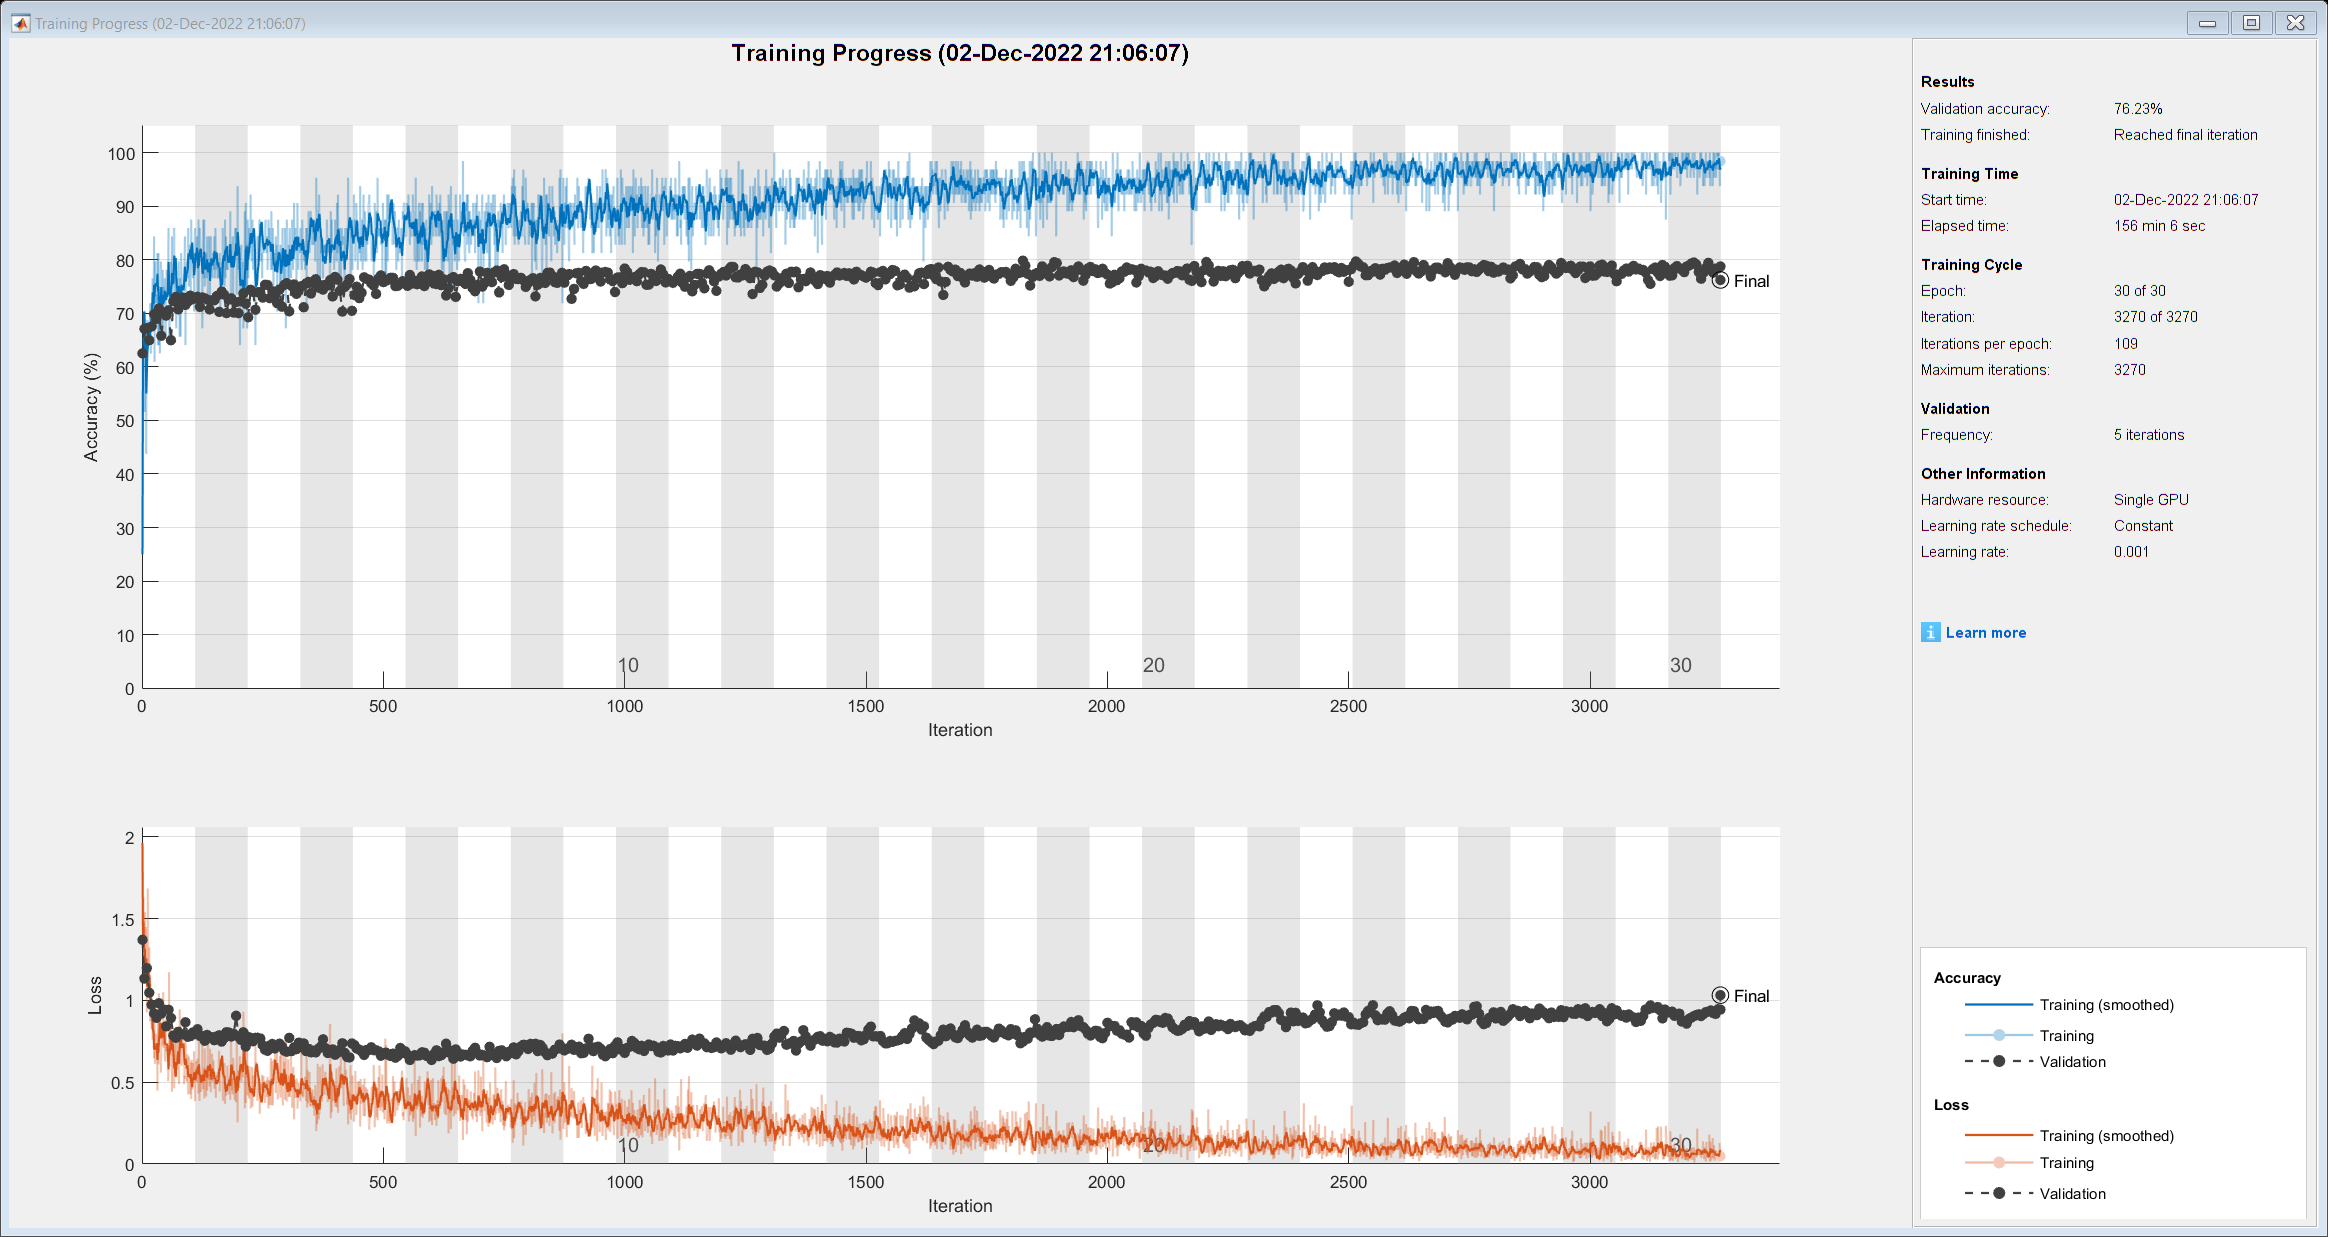

[net, traininfo] = trainNetwork(augimdsTrain,lgraph,opts);

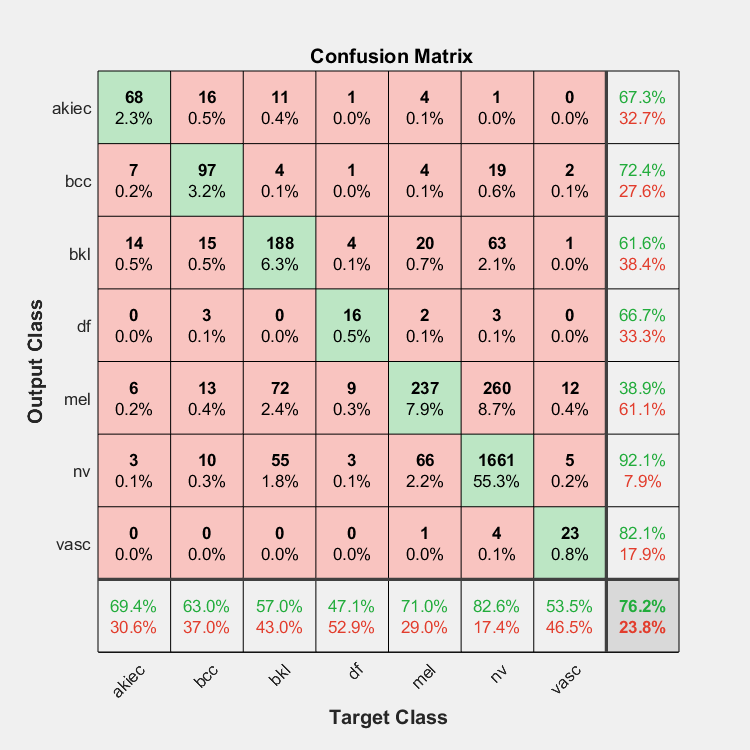

yPred = classify(net, imdsValidation);
yTest = imdsValidation.Labels;
plotconfusion(yTest, yPred)

figure
cm = confusionchart(yTest, yPred)

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [7×7 double]
         ClassLabels: [7×1 categorical]

  Show all properties


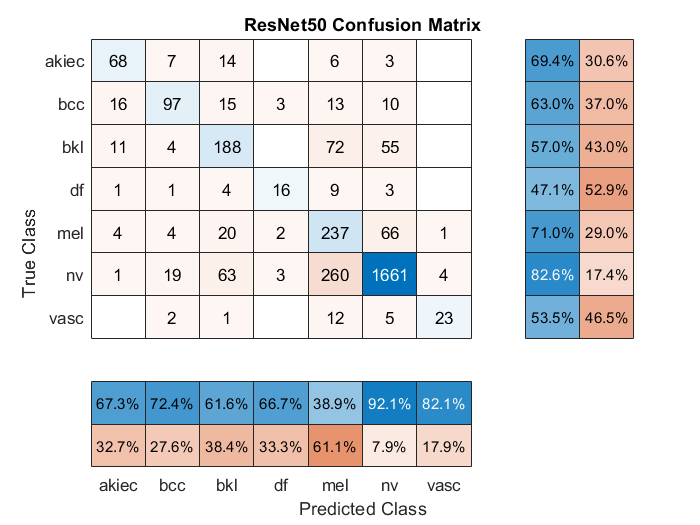

cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'ResNet50 Confusion Matrix';